% Contributors: Mustafa Saraoğlu, Laura Slabon, Erik Noack, Müjdat Korkmaz, Marta Valdes Martin

# Getting Started with MOBATSim

MOBATSim (Model-based Autonomous Traffic Simulation Framework) is a framework based on MATLAB® and Simulink® that allows users to develop automated driving algorithms and assess their safety and performance. By running a traffic simulation, the safety of the implemented component or algorithm can be measured on both the vehicle level and the traffic level, supported by 2D and 3D visualization options.

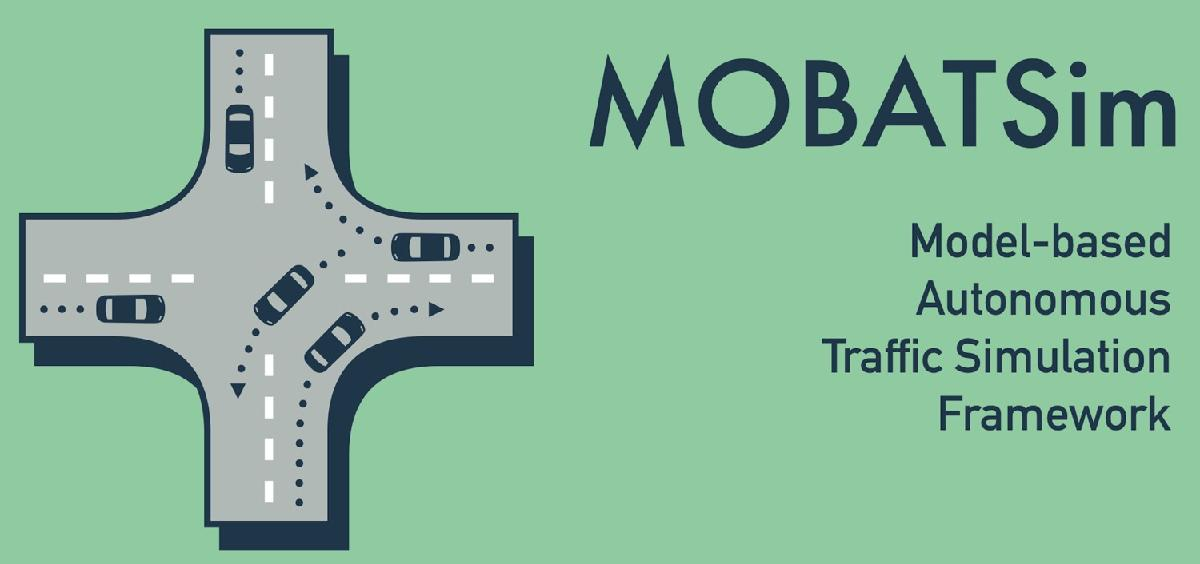

# The Structure of the MOBATSim Documentation

MOBATSim consists of many modular elements spanning from MATLAB Code to Simulink Model, from Graphical User Interface (GUI) to live script documentation that contains Latex formulas and explanations about certain parts in MOBATSim. Fitting the whole documentation into one live script would be exhaustive; therefore, we have decided to separate the whole documentation into a few separate live script files according to their subject and its depth.

After finishing this document, **"GettingStarted.mlx"**, you will learn how to use MOBATSim and the general structure of the framework. Then you should proceed with** "Documentation.mlx"** where you go one layer down into the details of MOBATSim. It involves details mainly about the implementation and its functional structure. Depending on your area of interest, you can choose one of the three more in-depth documentation. For example, if you want to go through the maths of the implementation that you have seen but want to learn further, then continuing with **"VehicleMotionPlanningControl.mlx"** is the right way for you, whereas if you first want to learn how things are visualized and the data structure behind the map, then you should proceed with **"MapStructureVisualization.mlx"**.

## Introduction

Automated driving systems tend to be more critical and sophisticated in the near future. The functional safety assessment for these systems becomes an urgent necessity for the transition to full autonomy. Testing these functions, which consist of decision and control algorithms with many variables and parameters, in a unified manner is a daunting task. Threat assessment has to be made for vehicles to avoid hazardous situations actively. This requires analyzing complex operational profiles such as routing, intersection management, and collision prediction in an environment where multiple automated vehicles (AVs) are in different positions and traveling at different speeds. There is a need for a comprehensive traffic simulation framework that models the functionality of these AVs and their interactions.

# MATLAB Version and Toolbox Requirements

MOBATSim is developed with Release 2020b of MATLAB® and Simulink®. There may be issues and unexpected errors with other versions. Therefore, for running MOBATSim, the requirement is **R2020b** version for the following MathWorks products and toolboxes:

- MATLAB®

- Simulink®

- Automated Driving Toolbox™

- Control System Toolbox™

- Deep Learning Toolbox™

- Model Predictive Control Toolbox™

- Robotics System Toolbox™

- Simulink 3D Animation™ (only required for the 3D Animation Virtual World)

- Stateflow®

- Symbolic Math Toolbox™

**If you use MOBATSim or you would like to mention MOBATSim, you can cite it as follows:**

Saraoglu, M., Morozov, A., & Janschek, K. (2019). MOBATSim: MOdel-Based Autonomous Traffic Simulation Framework for Fault-Error-Failure Chain Analysis. IFAC-PapersOnLine, 52(8), 239–244. Elsevier BV. Retrieved from https://doi.org/10.1016%2Fj.ifacol.2019.08.077

**BibTex:**

# Known Issues and Bugs

- Vehicles are not allowed to start or finish on the intersection points to avoid congestion.

- Bird's Eye View or DrivingScenarioDesigner APP might work slowly because of the size of the road network.

- Some road merges do not have safety guarantees which means that a vehicle just merging another road at the same time with another vehicle or there is a stopping vehicle at the merging point of the joining road may cause collisions.

- Changing the default sample time value of **0.02** or playing with different Simulink Solver options other than **"auto"** may cause unexpected behavior.

# -----------------------------------------------------------------------------

# Starting the Simulation and Visualization

MOBATSim has a project file that includes the Simulink files and their paths. The project can be opened by double-clicking on ***MOBATSim.prj*** and a **GUI** will appear, which can be used to start the simulation. Simply click on the **Start Simulation** button and wait for the simulation to start.

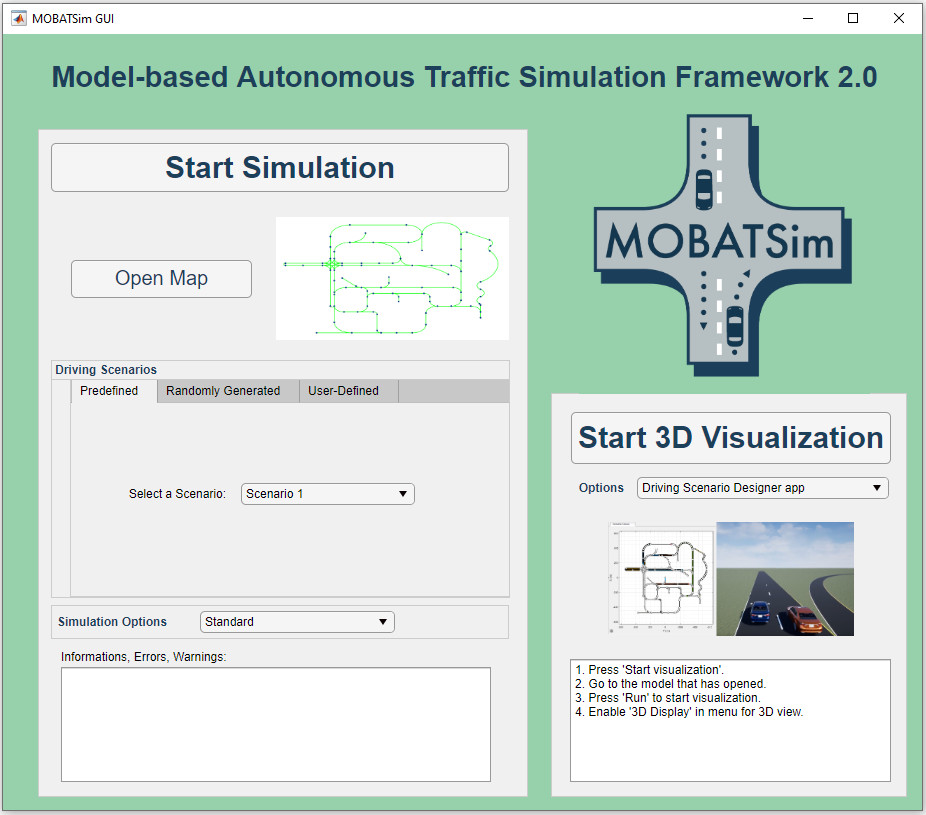

MOBATSim Simulink file will be automatically opened and run to start the simulation. The map consists of nodes and edges shown on a 2D plot. The vehicles will appear as red circles with their speeds shown in meters per second. Roads are illustrated with bright green, and the planned paths of the vehicles will be dynamically highlighted with different colors. At this stage, the simulation is running using the Simulink model and the corresponding MATLAB m-files, simultaneously logging the vehicle data. Therefore the simulation needs to be completed for further visualization.

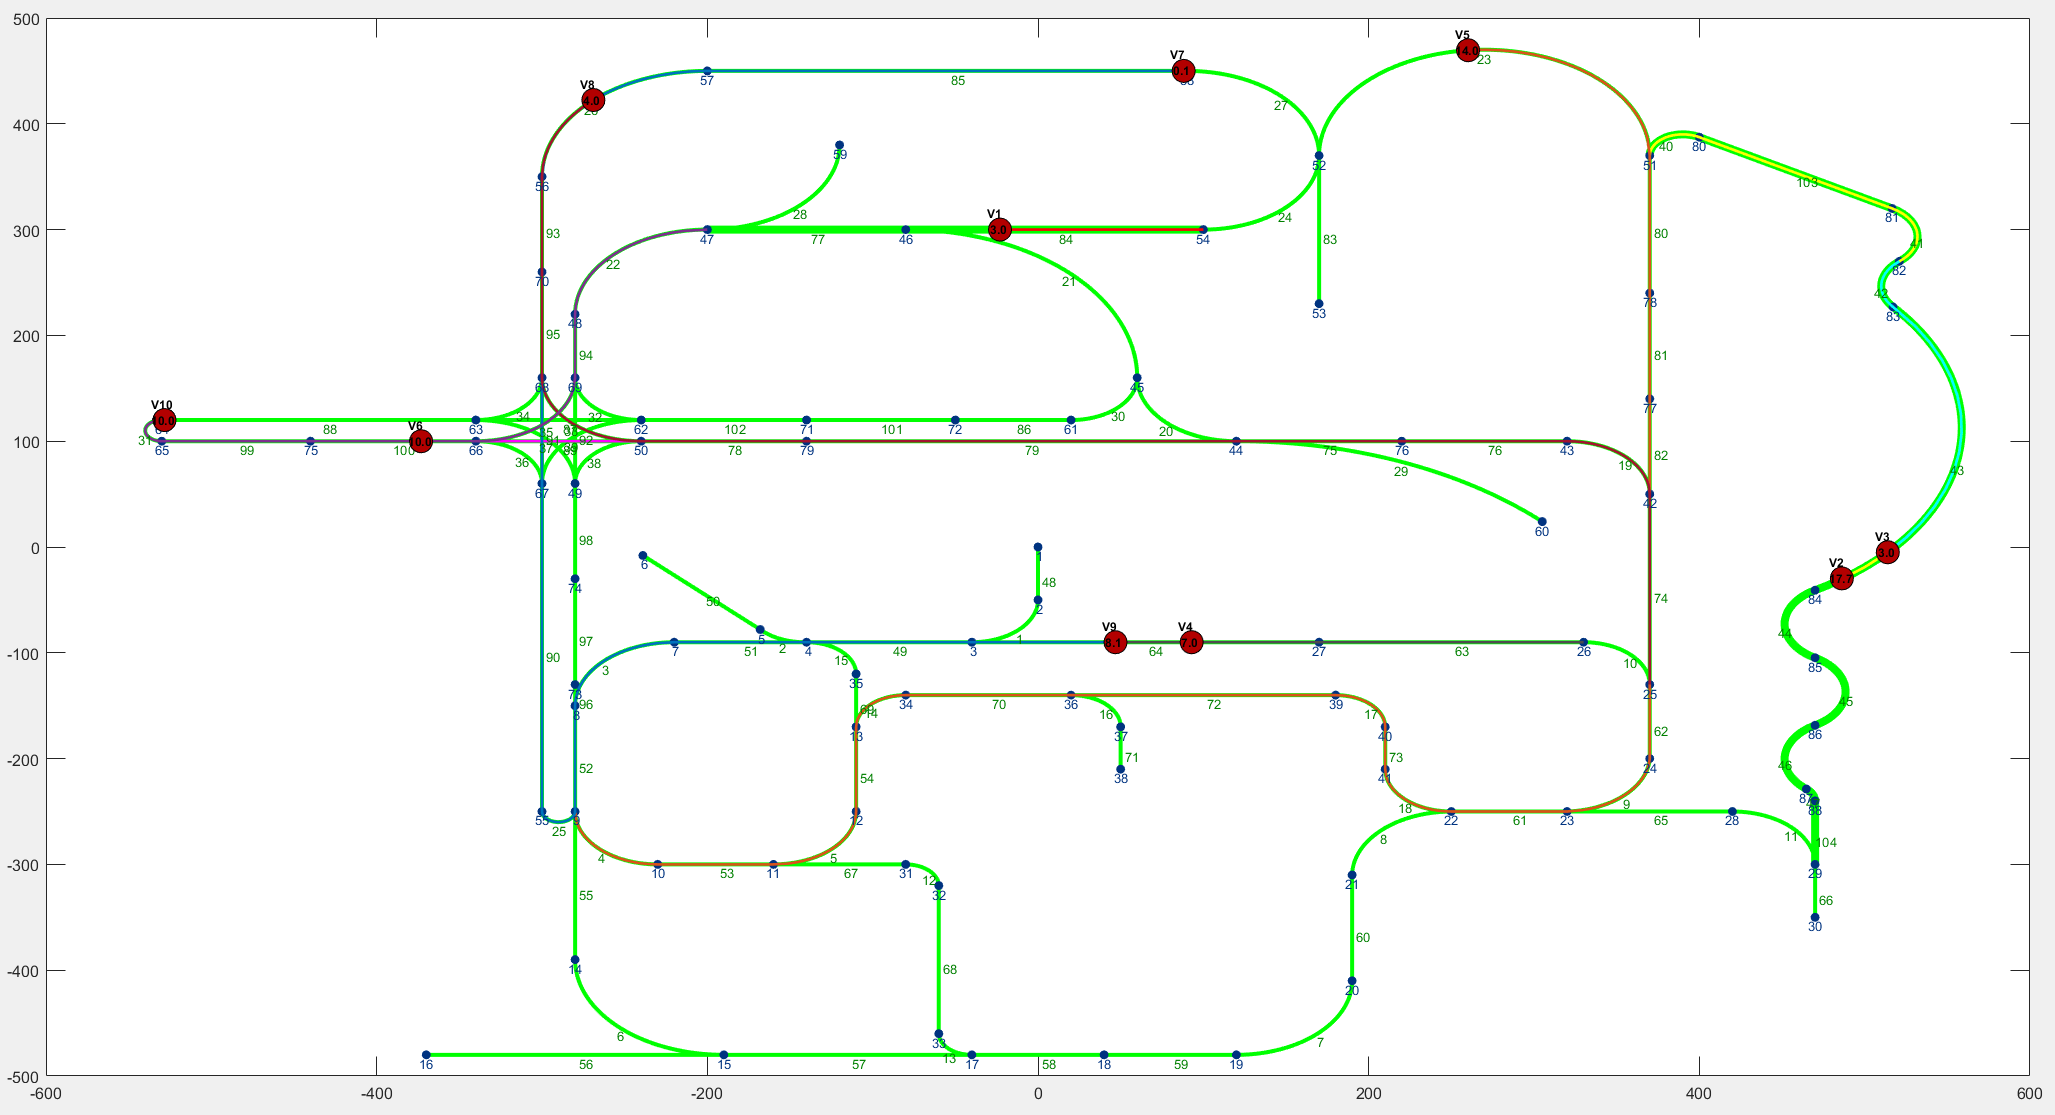

After finishing the simulation without an error, the logged vehicle data with time is saved in the base workspace for a more sophisticated analysis or visualization. MOBATSim supports the following visualization options:

- **Simulink 3D Animation**

- **Bird's Eye View**

- **Cuboid World and Unreal Engine 4.**

## Simulink 3D Animation

Simulink 3D Animation world is one of the oldest parts of MOBATSim. Originally MOBATSim was designed according to the coordinate system of the 3D World Editor available in MATLAB. Therefore the units are a bit out of scale, and it is currently being used as an amusement park. However, if you would like to create some interesting visuals, such as dinosaurs flying over the city while vehicles drive autonomously in the Mobatkent, you can check the model by opening the *src/Visualization/Mobatkent.WRL* file.

To simulate this 3D World, you need to choose **Mobatkent** as the visualization option from the GUI or open the Simulink model for 3D Animation from *src/Visualization/Animation3D.slx*.

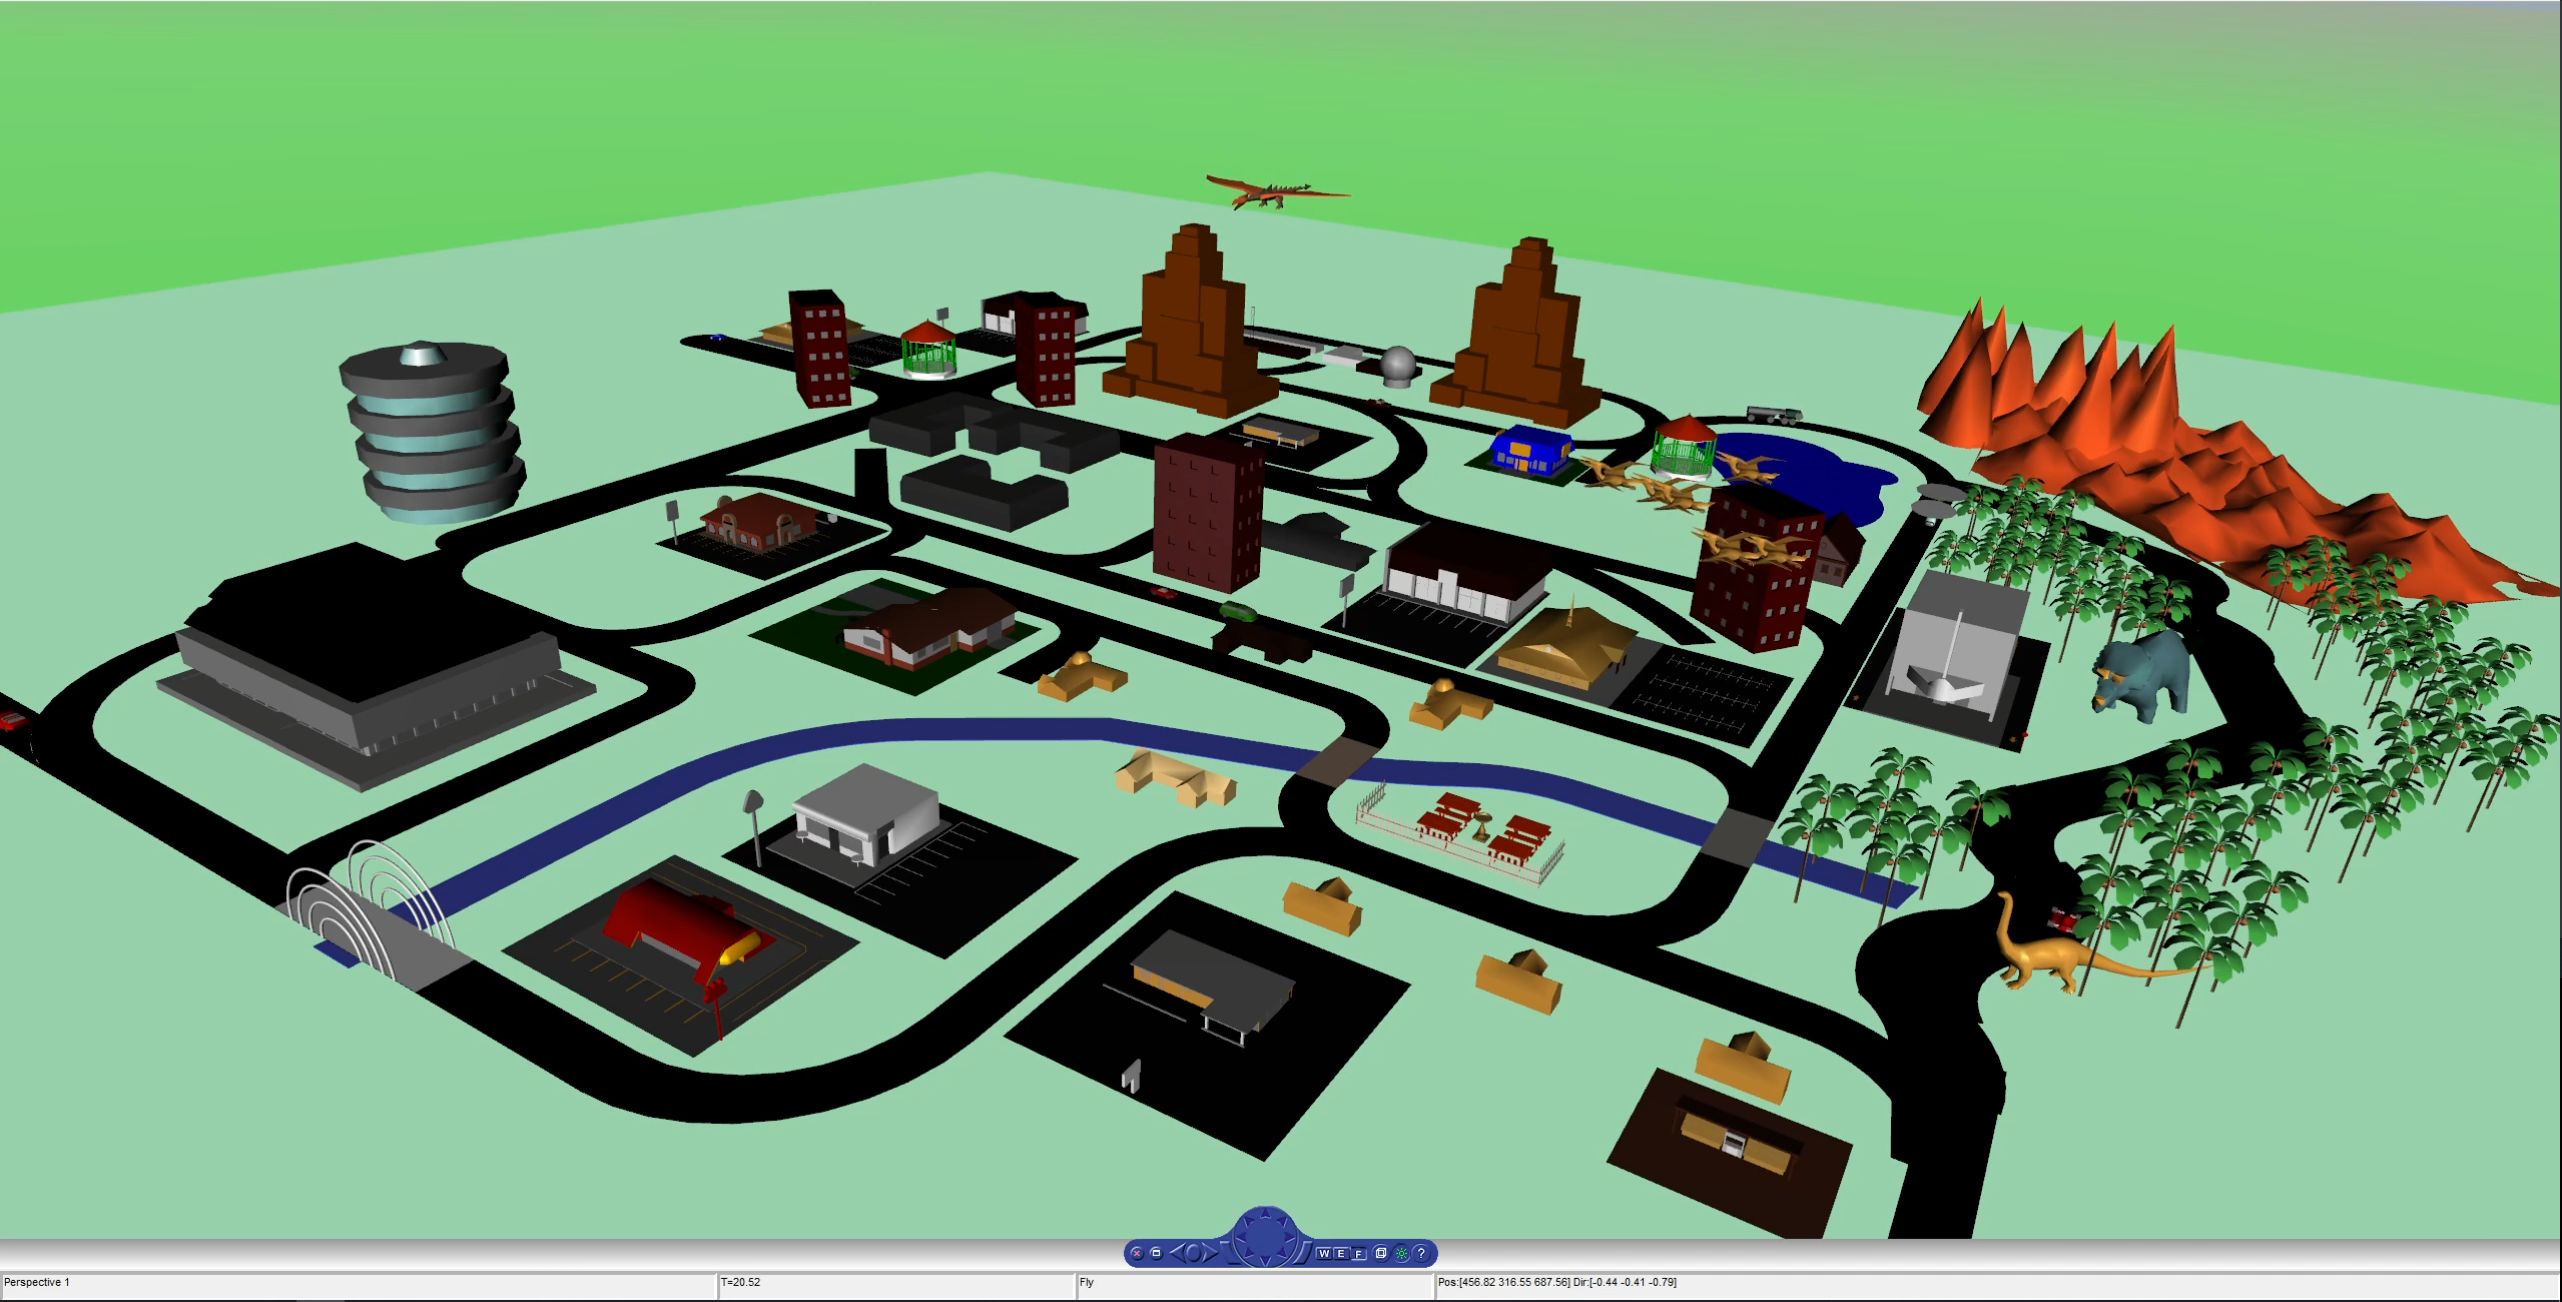

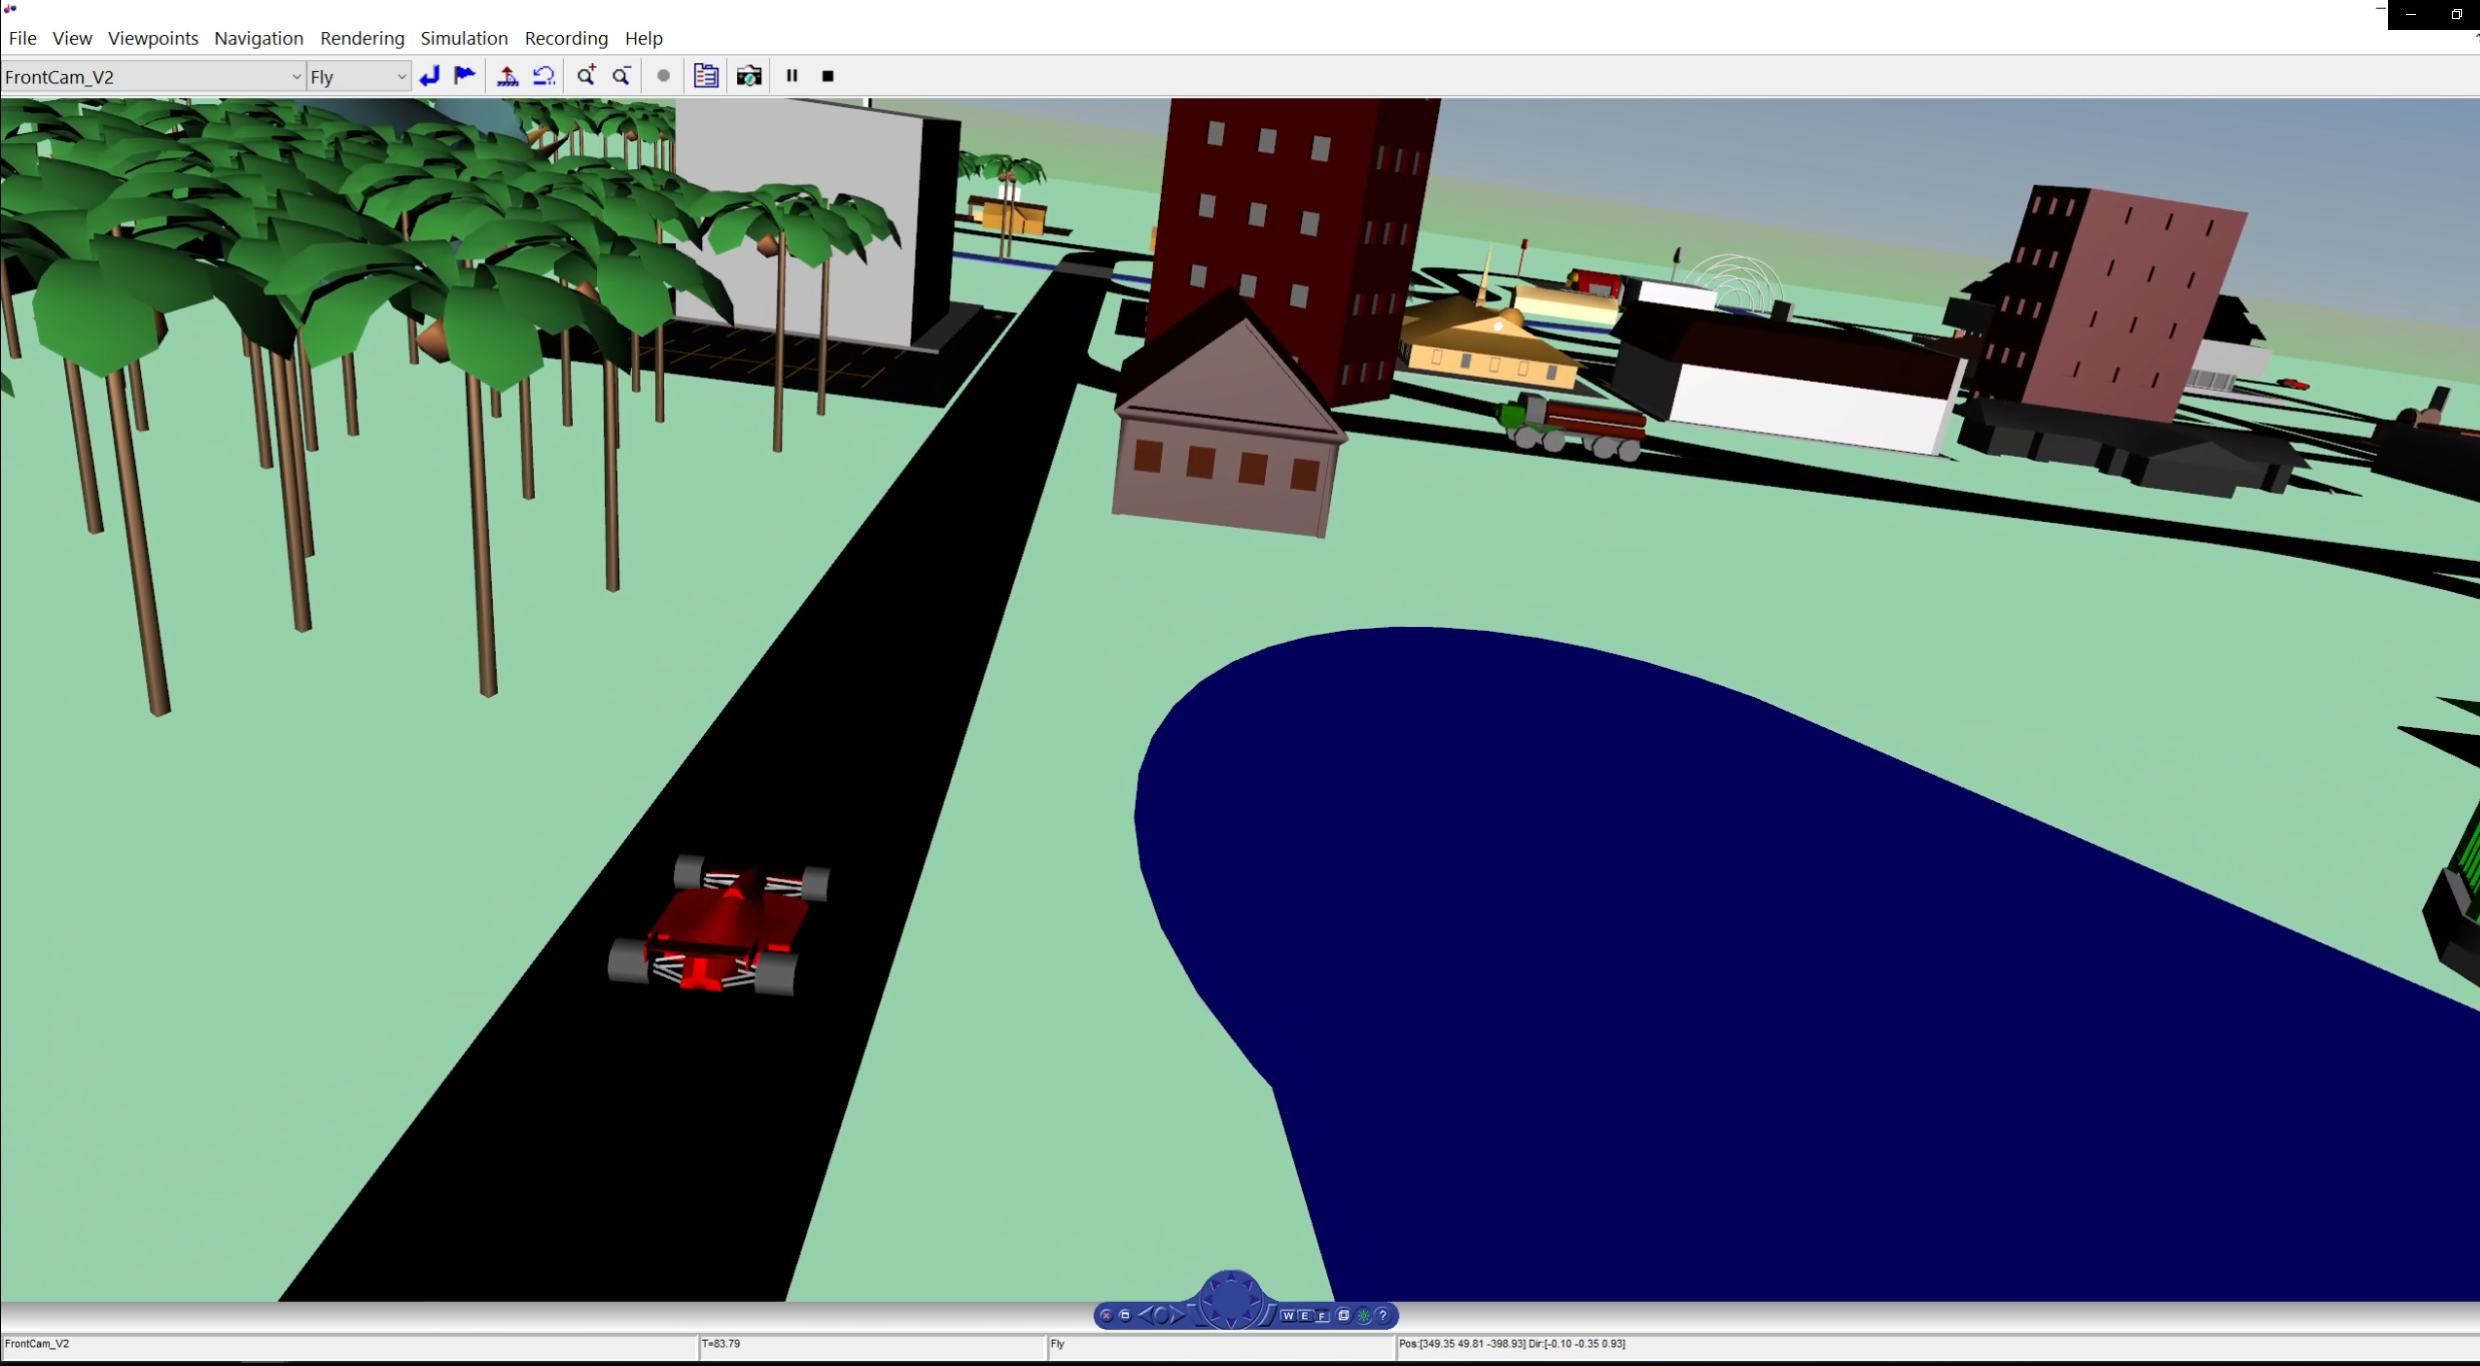

This map is obsolete, and the extended parts of MOBATSim, such as double lane roads, have not been applied to this map. Other visualization methods explained below are much more accurate and useful for scientific purposes.

## Bird's Eye View

After completing the simulation, just like the previous visualization, the same logged vehicle data can be used for the other visualization options. **Bird's Eye View Scope** provides a more simplistic visualization to assess the safety of the developed algorithms up to a very high resolution. It provides two views. **Vehicle Coordinate View** focuses on the **Ego Vehicle**, which is defined as **Vehicle 2** and moves the coordinate according to the vehicle's orientation. **World Coordinate View** can be used to observe and focus anywhere on the map by panning and zooming in. 

Some coordinate transformations are necessary to run the Bird's Eye View because the coordinate system of MOBATSim was firstly developed according to the 3D Animation coordinate system. The necessary transformations are done by a script (*src/Visualisation/run_Bird_eye_view.m* script) that generates the trajectories from the logged vehicle position data as time series. The instructions on how to open the Scope from the APPS tool strip are shown in the Simulink model itself.

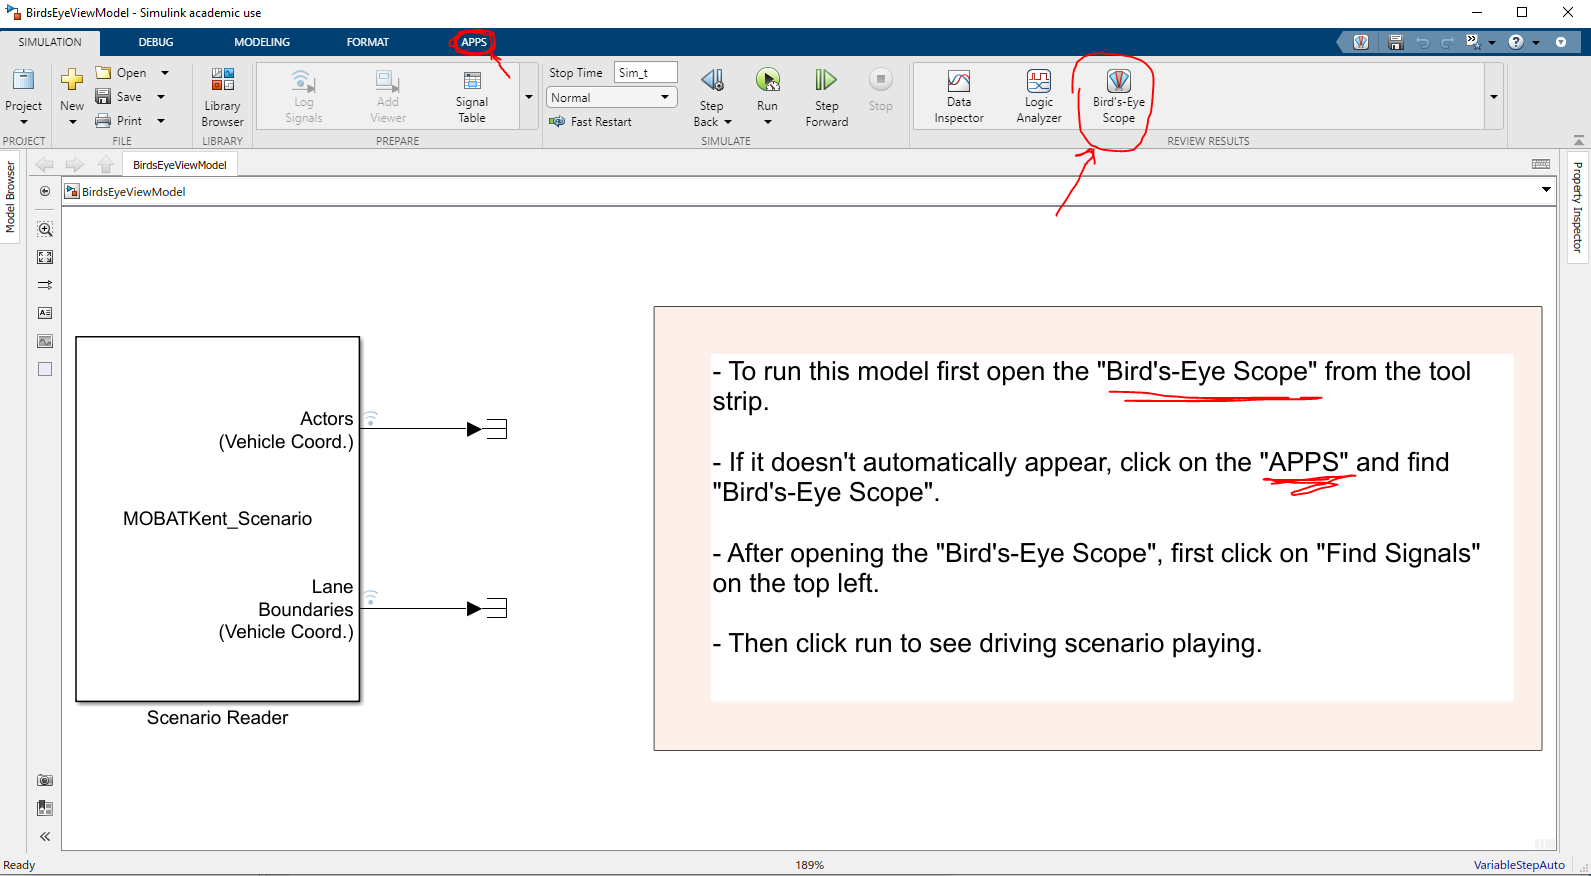

After opening the Bird's Eye Scope, click on **Find Signals** on the top left of the opened window. After the vehicles are placed on the map, you can click on the **Run** button to visualize the driving scenario that you have run to log the data.

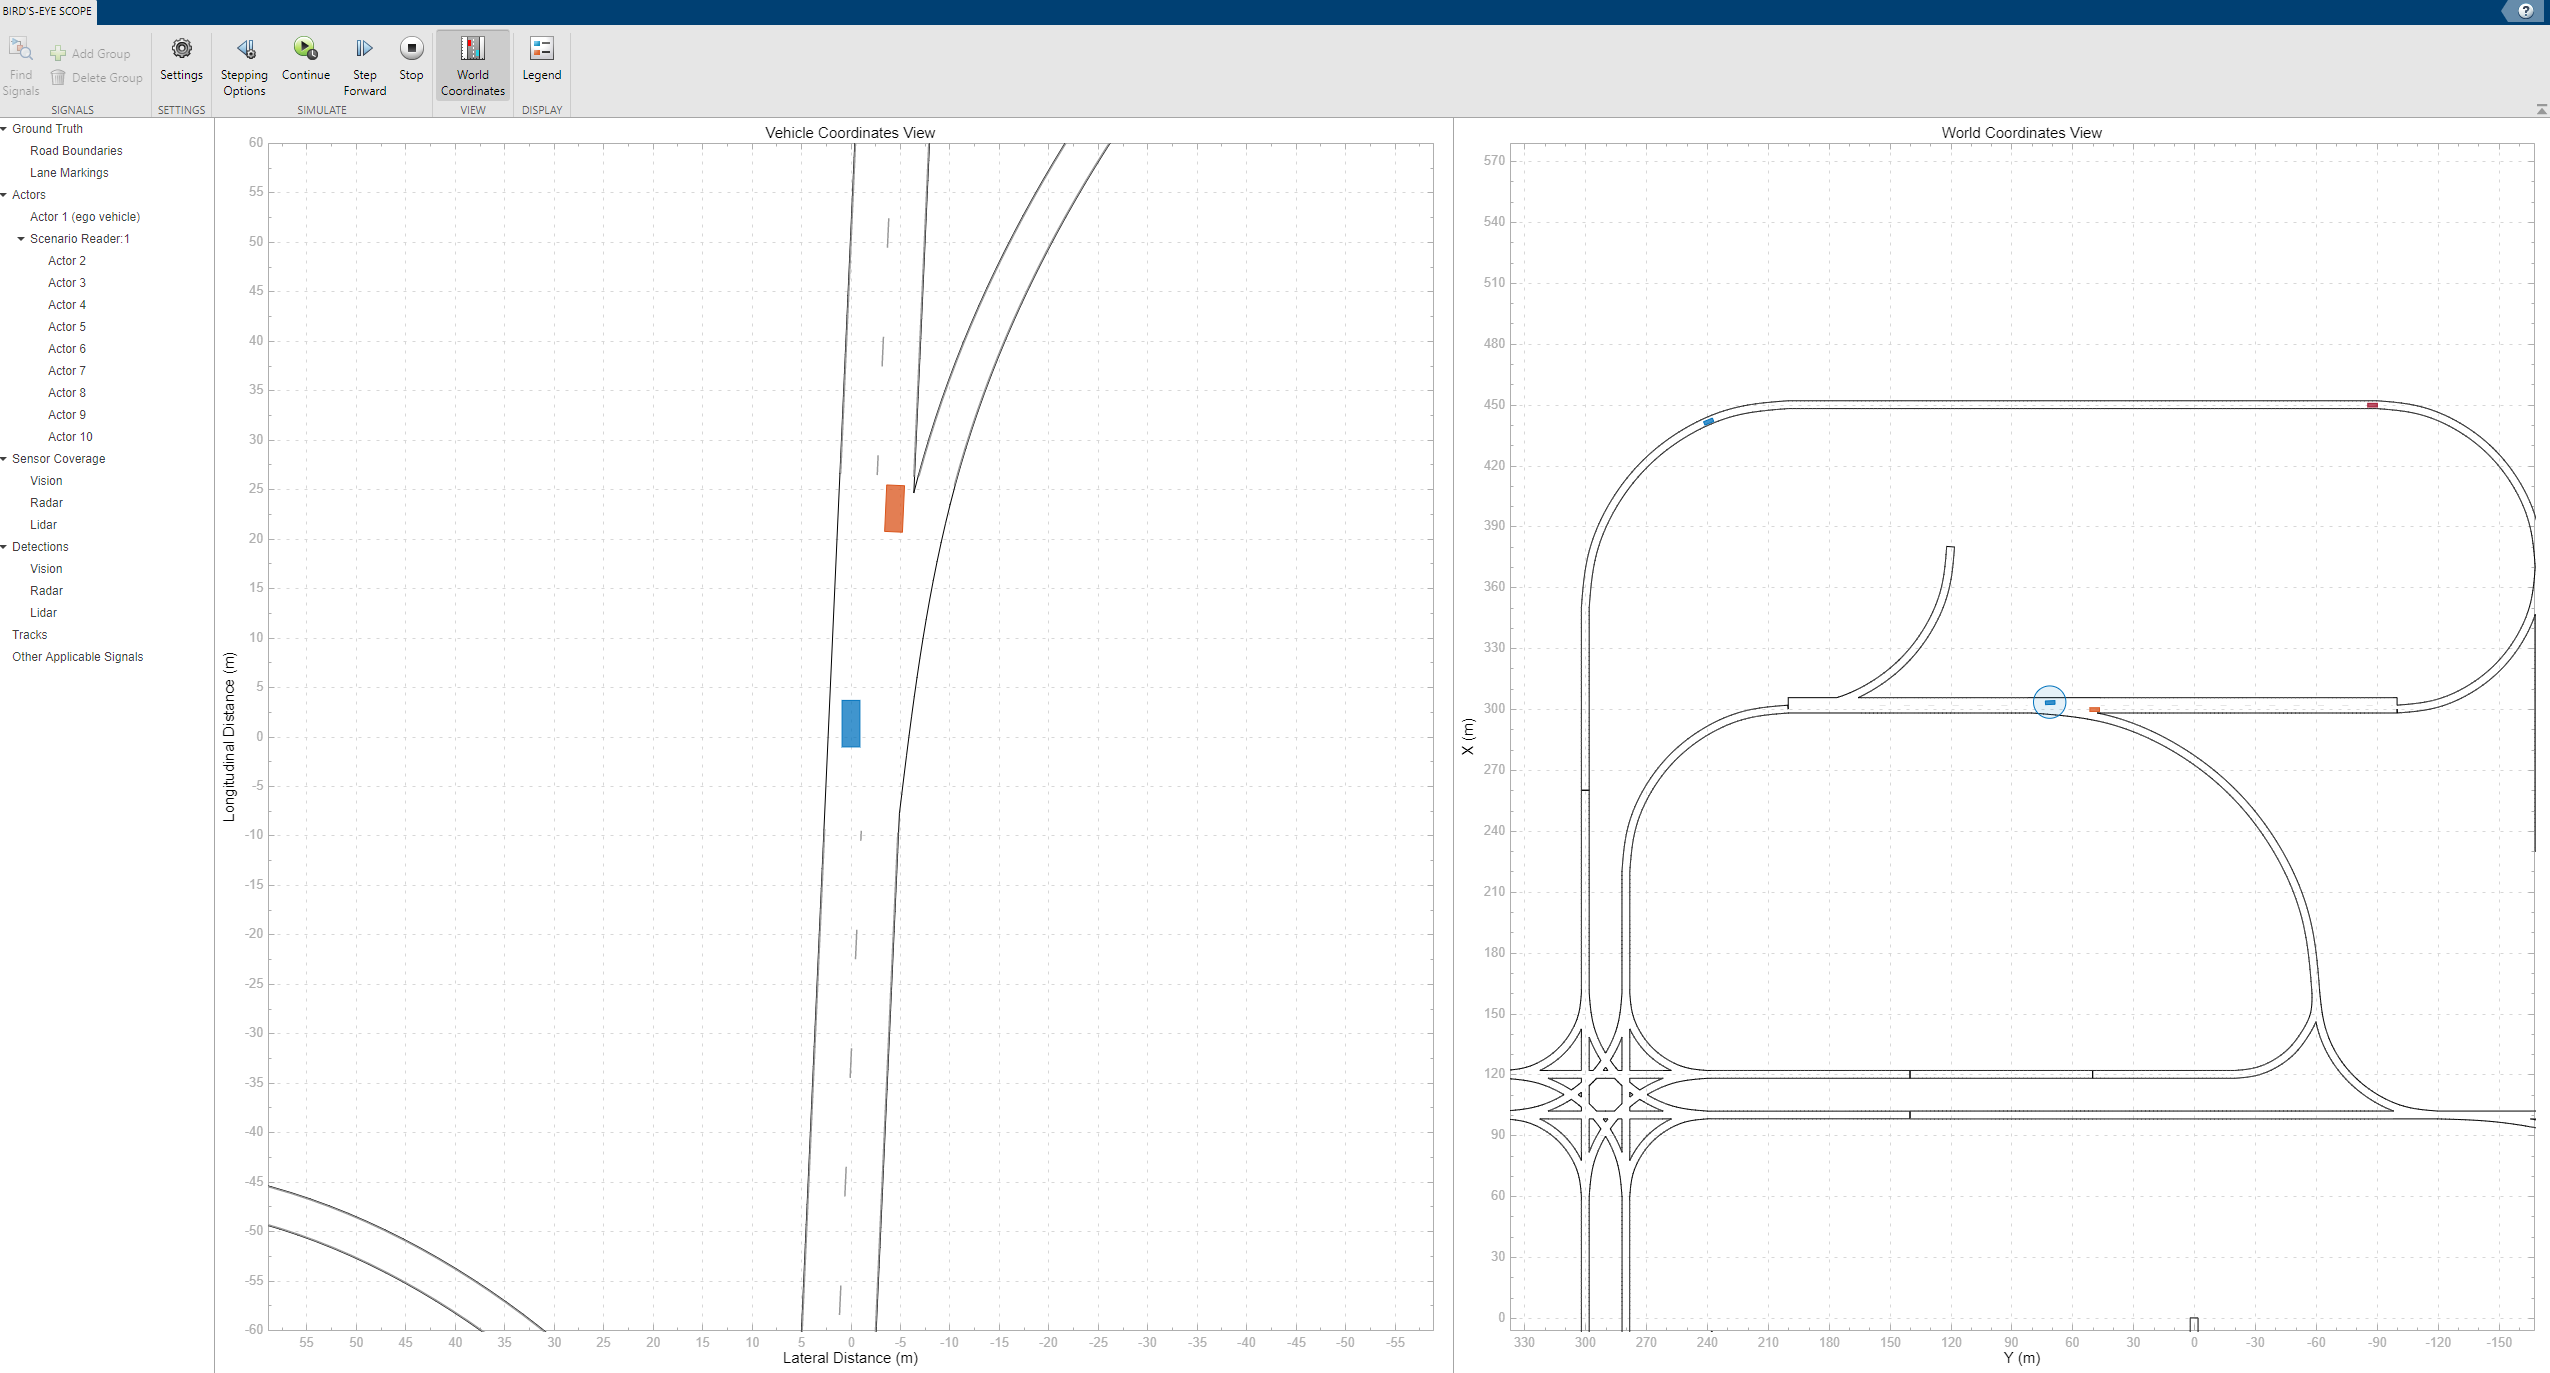

## Cuboid World and Unreal Engine 4

Cuboid world and the Unreal Engine 4 visualization also run similarly to Bird's Eye View. The coordinate transformation and the opening of the driving scenario directly in the **Driving Scenario Designer APP** are resolved by running a script named  *src/Visualization/openScenarioInApp.m* just like the rest of the visualization scripts.

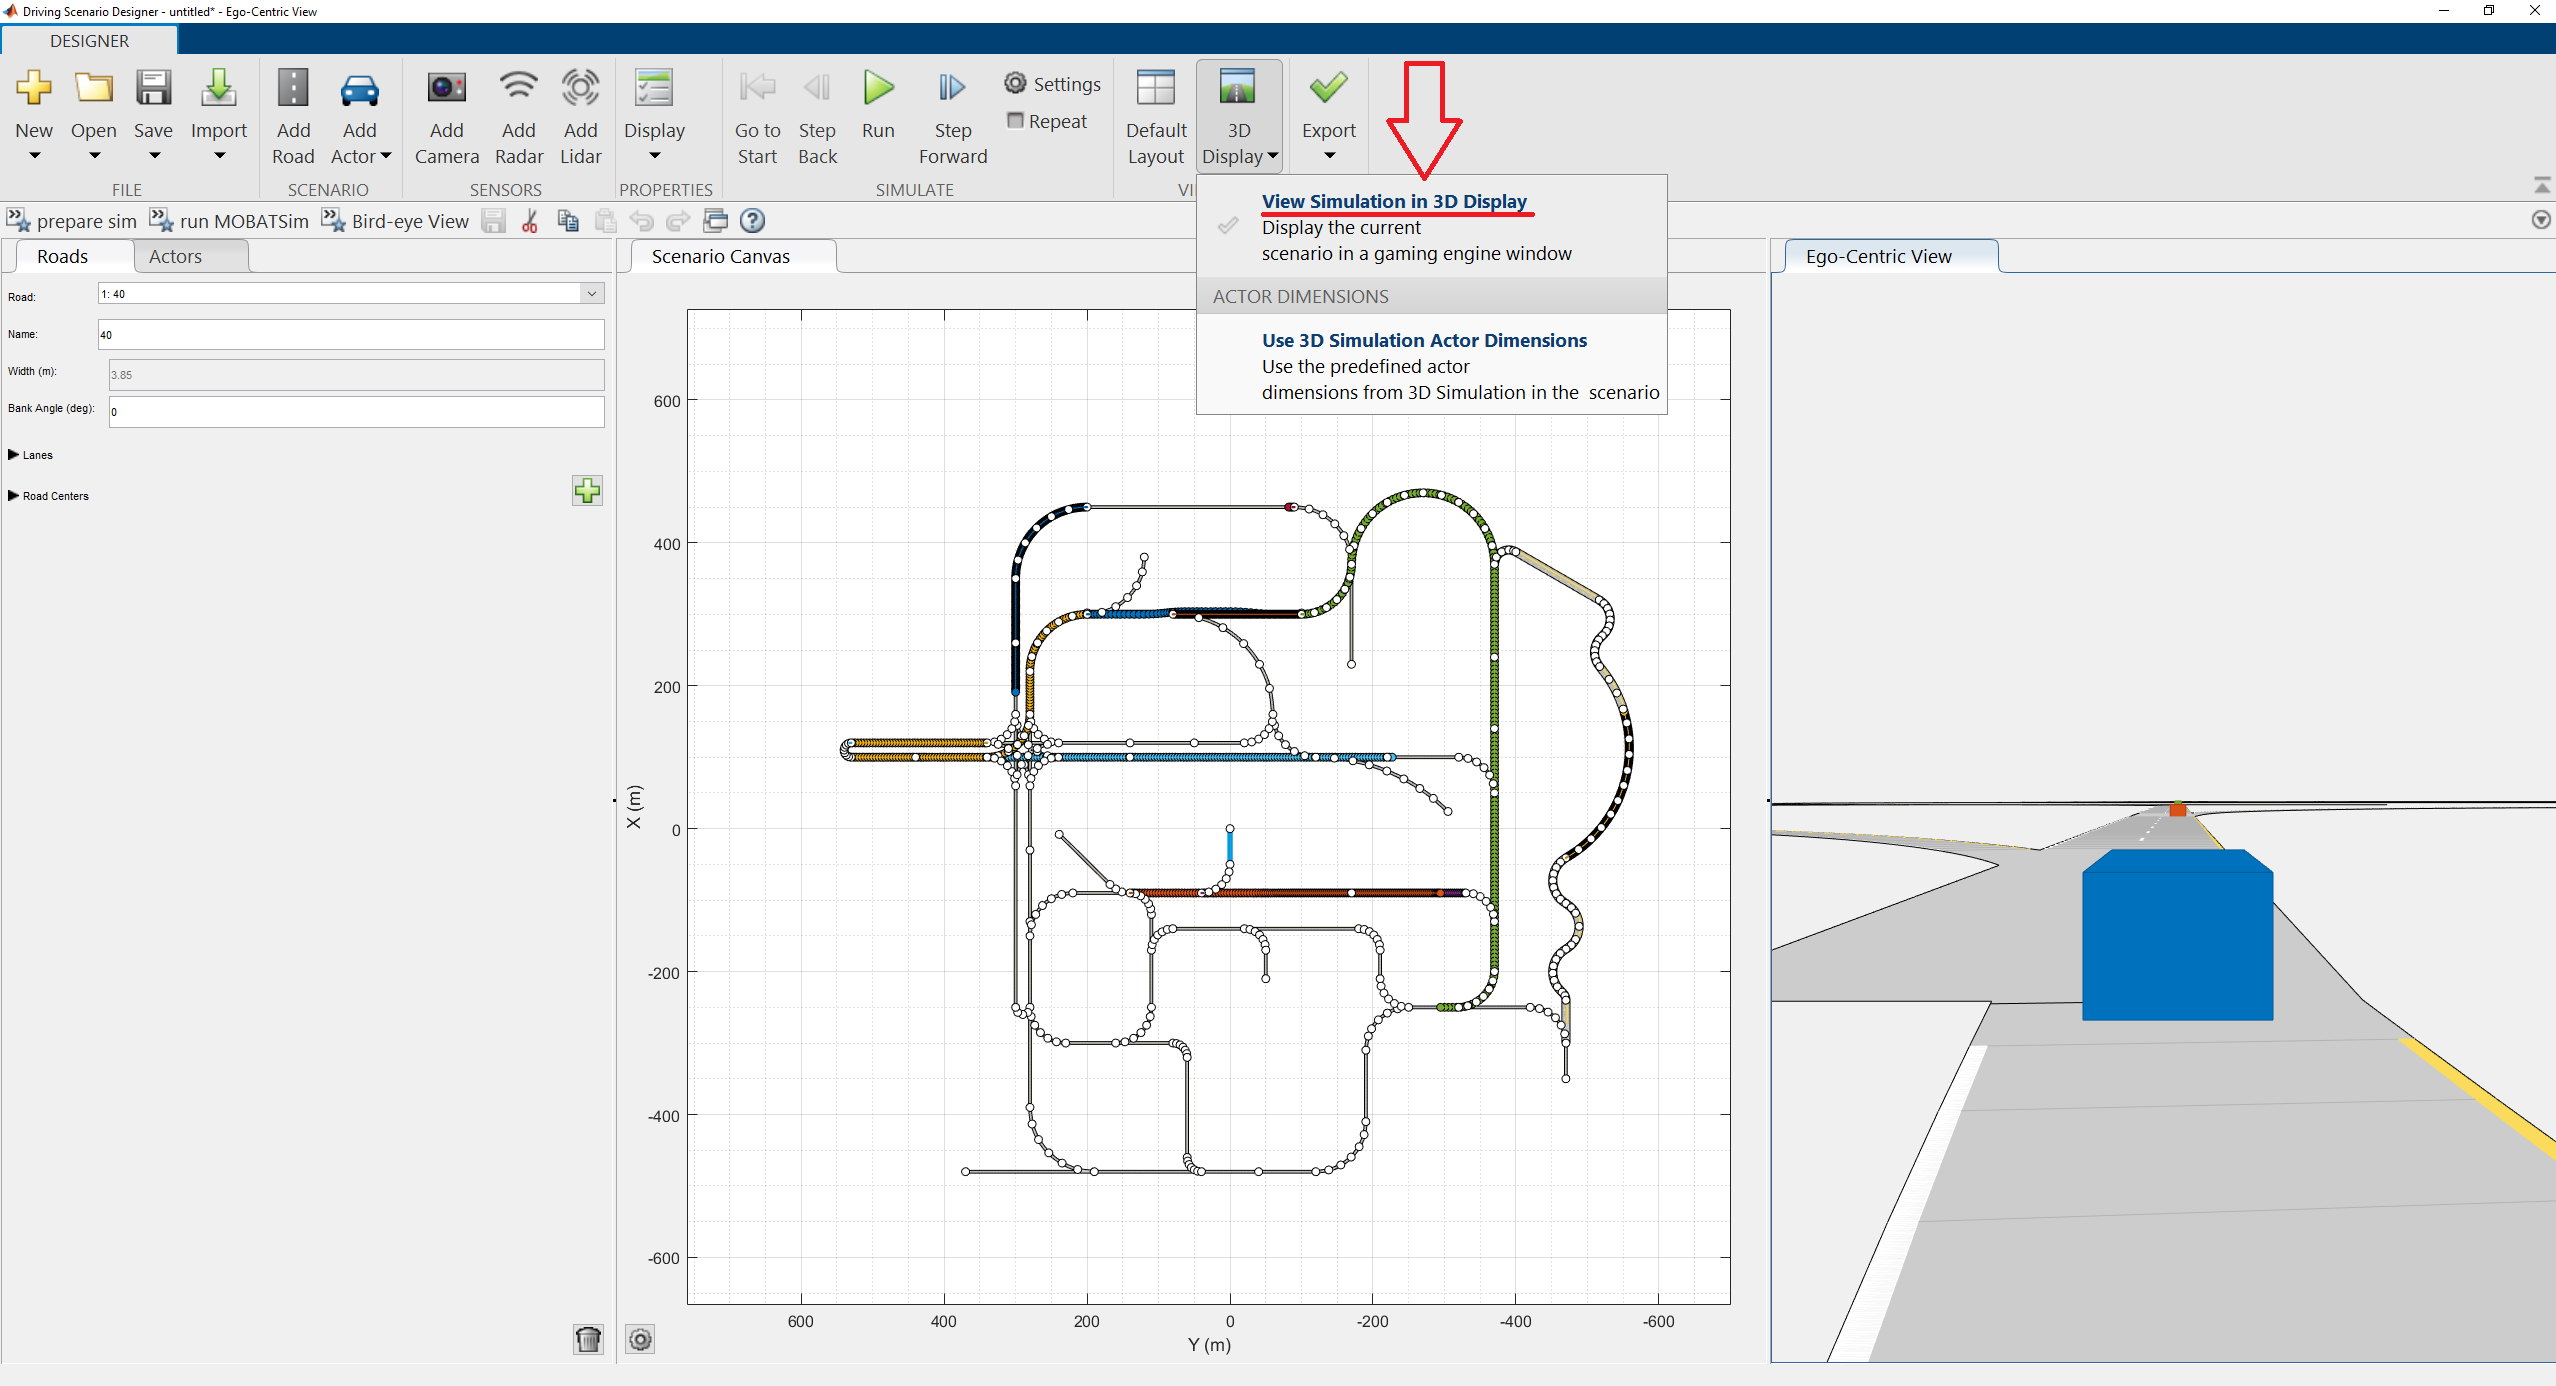

After running the *src/Visualization/openScenarioInApp.m* script, the newly opened window will show all the vehicle trajectories on the map with a Cuboid vehicle view on the right side. If you just click **Run** the Cuboid world simulation will start. However, if you would like to simulate the same driving scenario using Unreal Engine 4 for more realistic and sophisticated graphics, then you have to click on the **3D Display** on the top pane and click on **View Simulation in 3D Display**. It might take some time, but after the Unreal Engine 4 window appears, you can simply click on the same green **Run** button and watch the vehicles drive in the Unreal Engine environment.

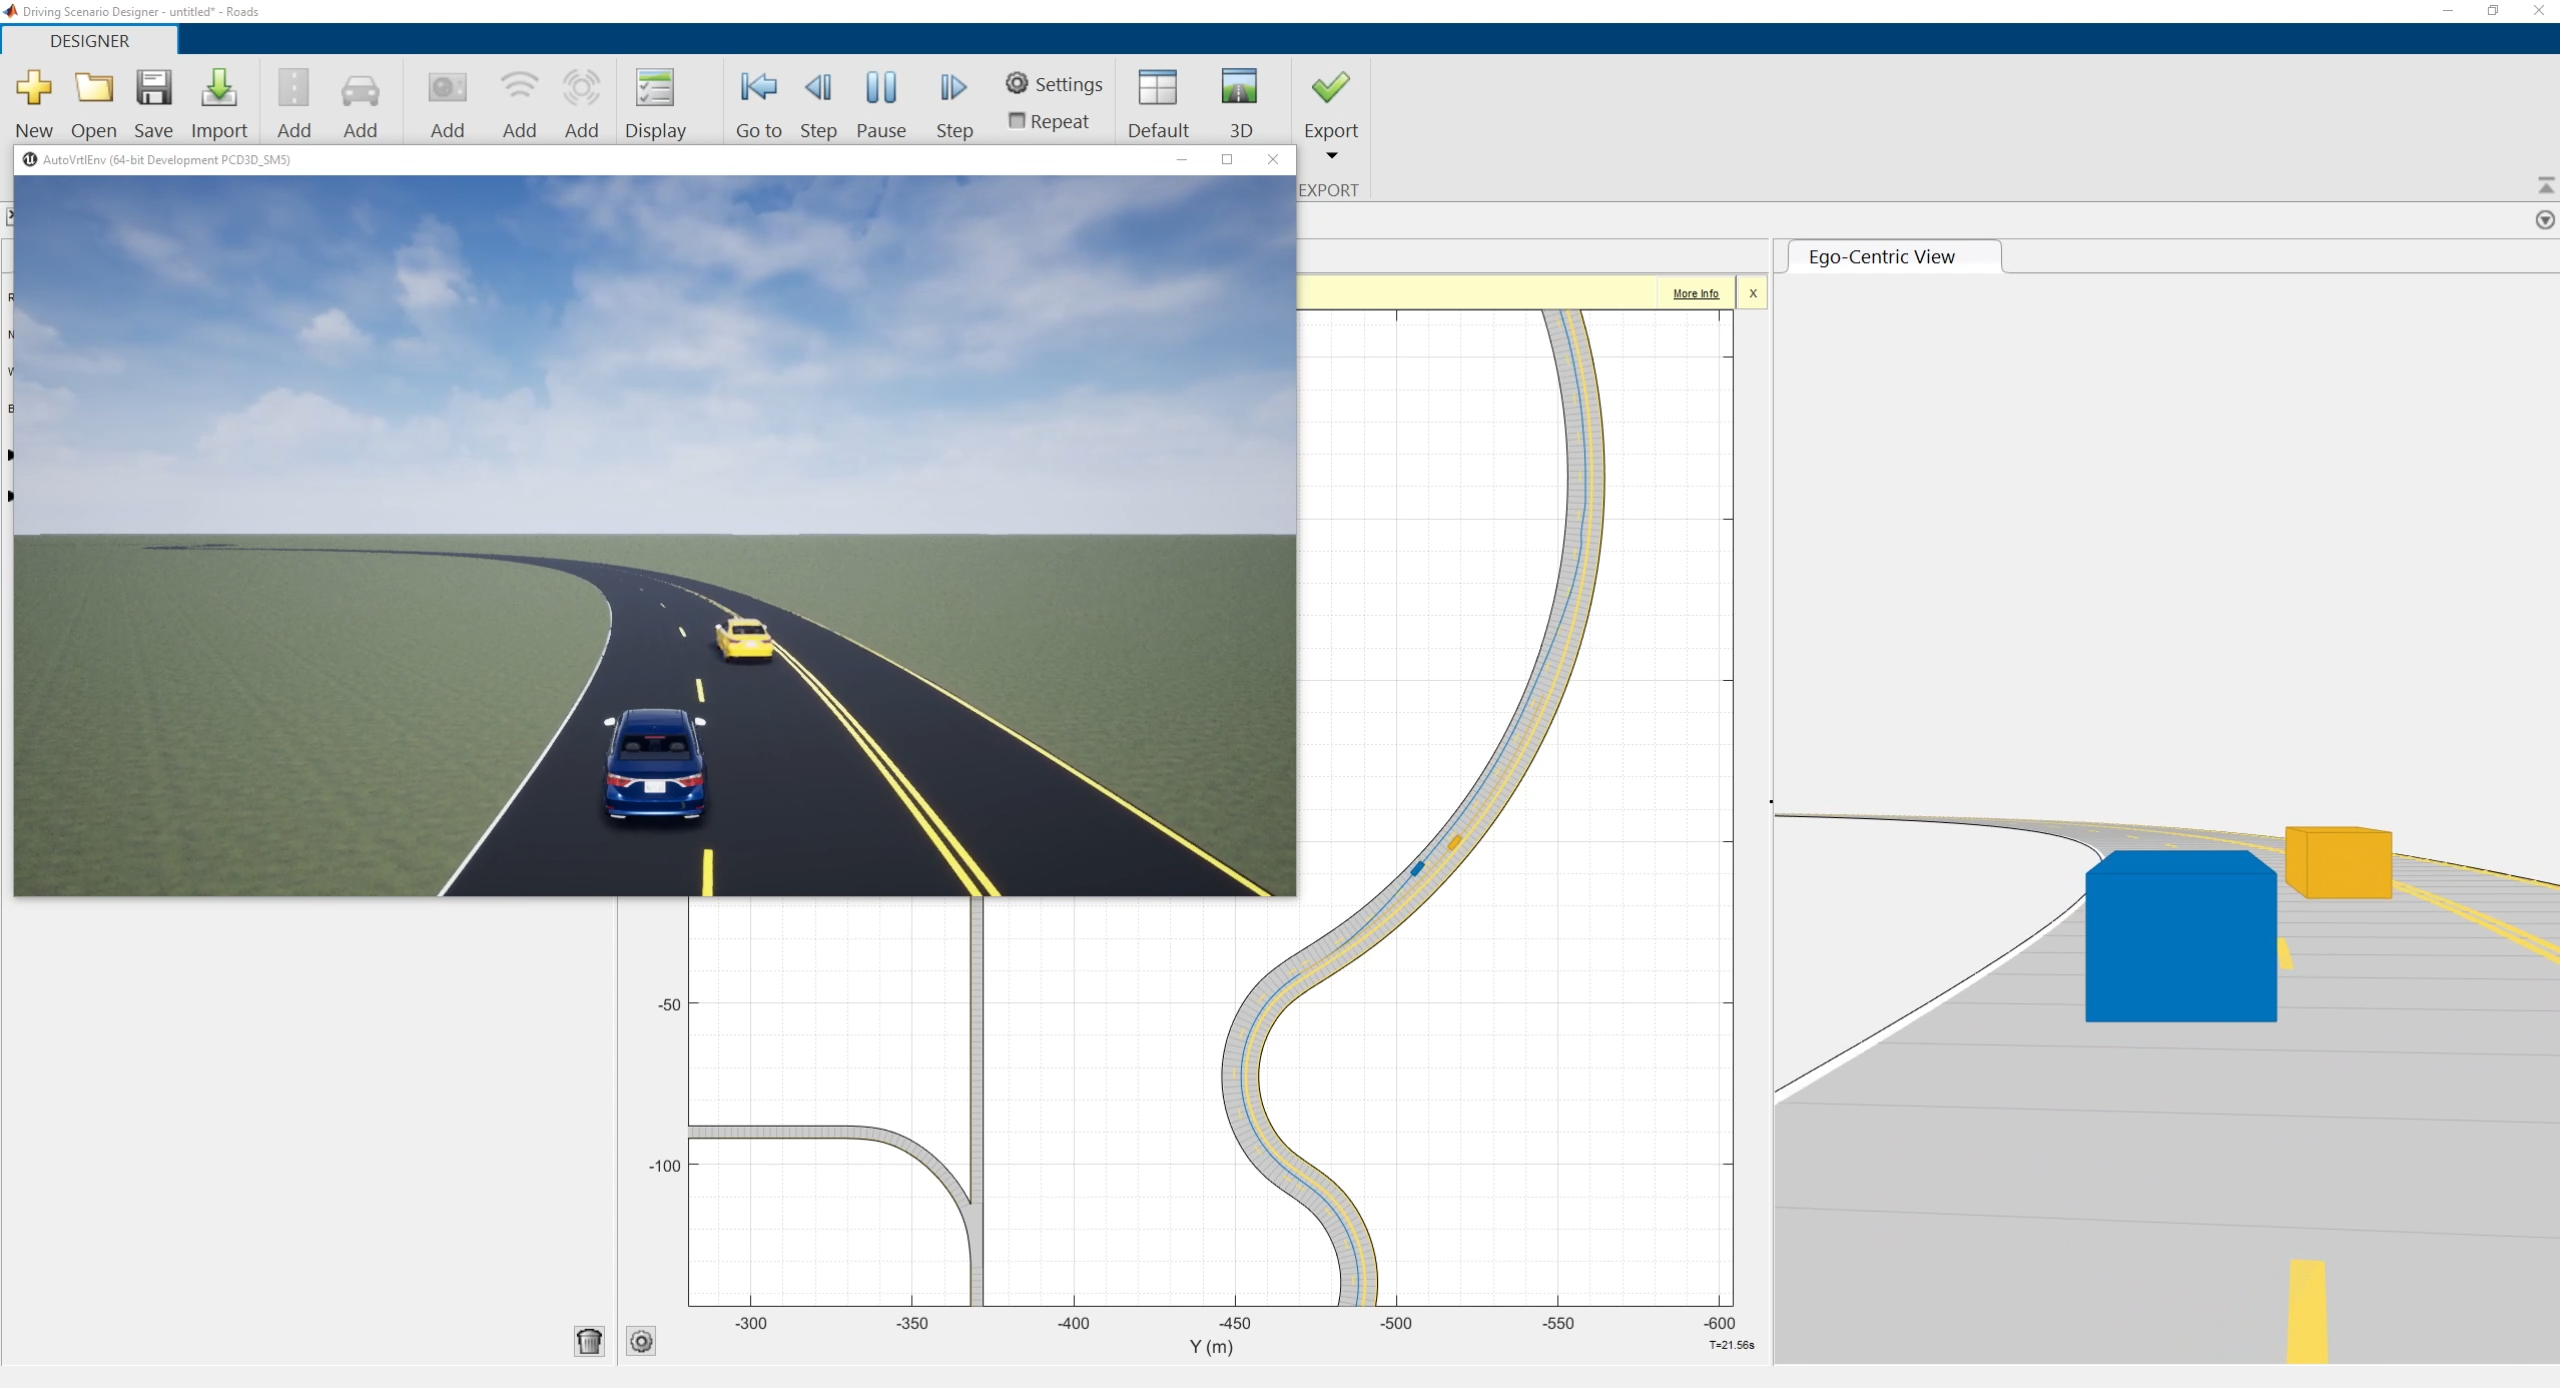

# -----------------------------------------------------------------------------

# Tutorials

Now you know how to run the simulation but the best way to learn how MOBATSim works is to interact with it and make changes. In the live script *docs/Documentation.mlx*, you will find a more detailed and in-depth workflow of MOBATSim. However the tutorials below are designed to provide you a quick intuition about MOBATSim without reading the whole documentation.

## 1- Change Vehicle initial Starting Points and Destination Points

Now go ahead and try to find the initial driving scenario file. A driving scenario defines the **starting points**, **destination points**, and the **maximum speeds** of the vehicles. You can simply look for the function:                                                 *src/Scripts/Load Data/load_scenario.m*. There you should see 10 starting points and destination points for 10 vehicles. Try to change some of them. Note that the roads are **one-way roads**, so the destination points should be reachable from the starting points. Otherwise, the path planner of the vehicle throws an error. Here is the portion of the code you can edit (it is commented out below with % to make sure that it doesn't get executed when you run this script as a whole):

After changing some of the **startingPoints**, **destinationPoints** and **maxSpeeds **go ahead and run the simulation with:

## 2- Debug the Simulation and View Vehicle States

The purpose of this task is to learn how the blocks and code work together. Let's start a simulation first and then try to pause it and view some of the state variables at a given time.

When you run the simulation, the MOBATSim Simulink model was opened. As mentioned before, a more detailed explanation of the elements below are given in *docs/Documentation.mlx*. Our task is to simply choose a block and interrupt it by placing a **conditional breakpoint**.

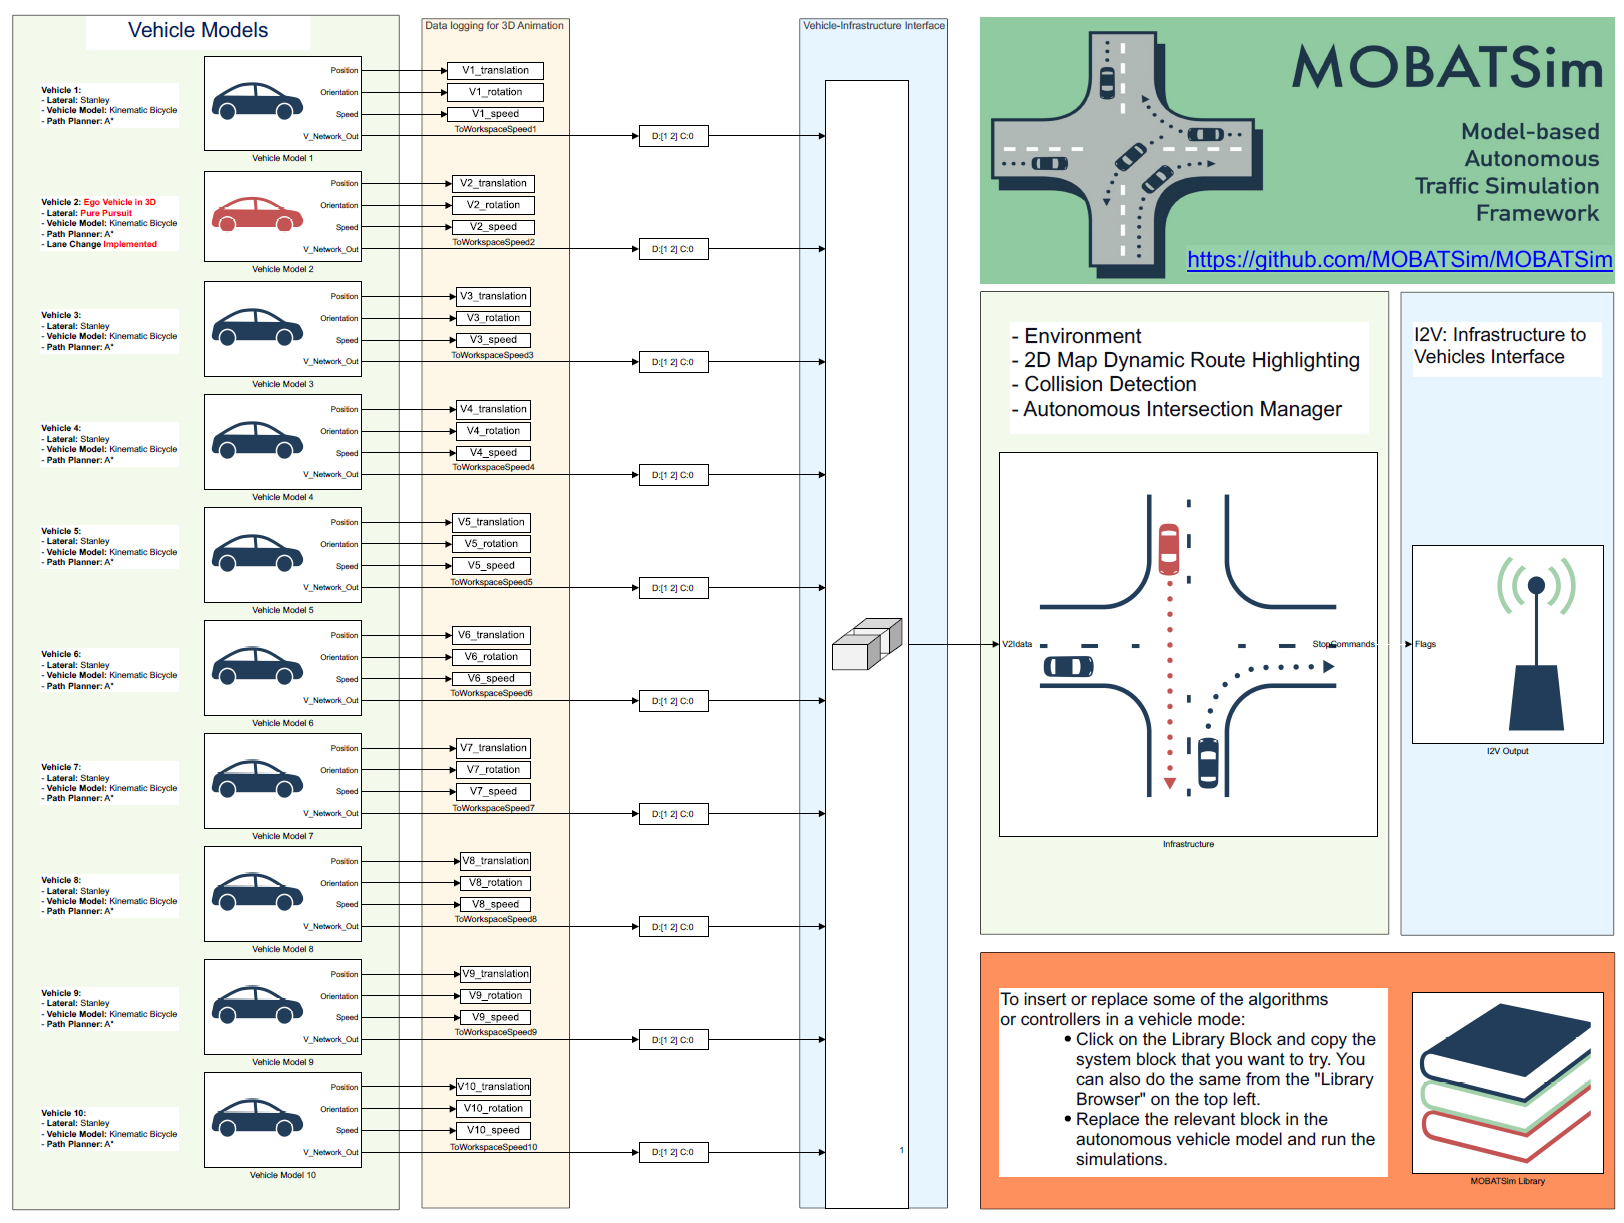

Let's zoom on **Vehicle Model 1** and left click on the bottom left corner (on the small arrow that appears) to **look under the Mask**.

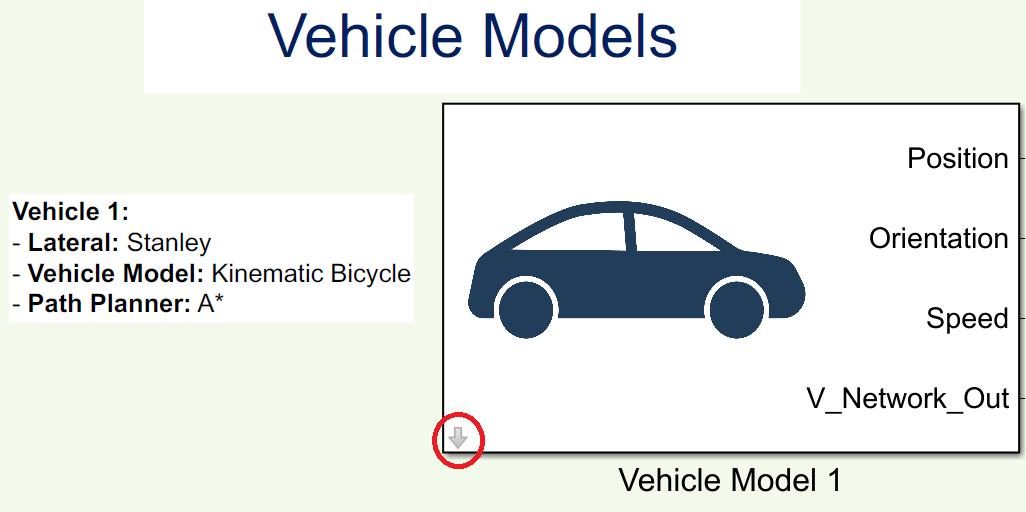

The autonomous vehicle architecture in MOBATSim is shown below. Here let's choose the **Behavioral Planner** to set a breakpoint. Double click on the **Behavioral Planner** block and a small window will appear. Since this block is a **MATLAB System Block**, it works like a **class** with **properties** and **methods**. From this window, you need to click on the source code to view the *src/VehicleDrivingMode.m* Class.

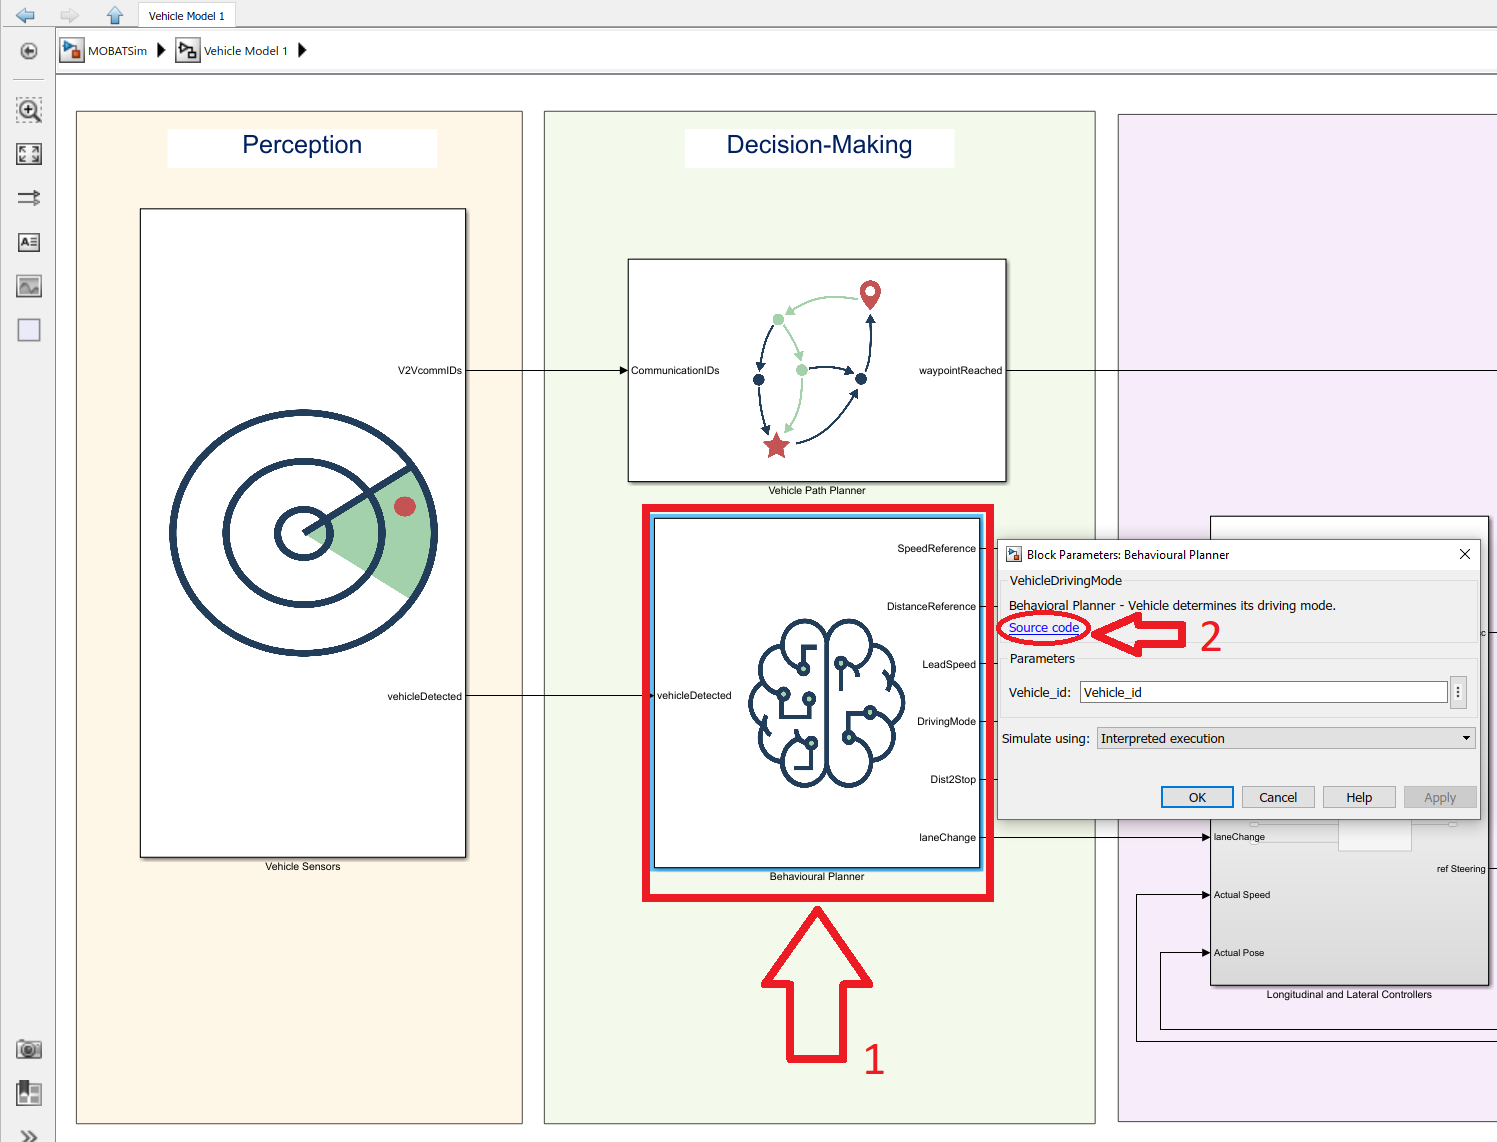

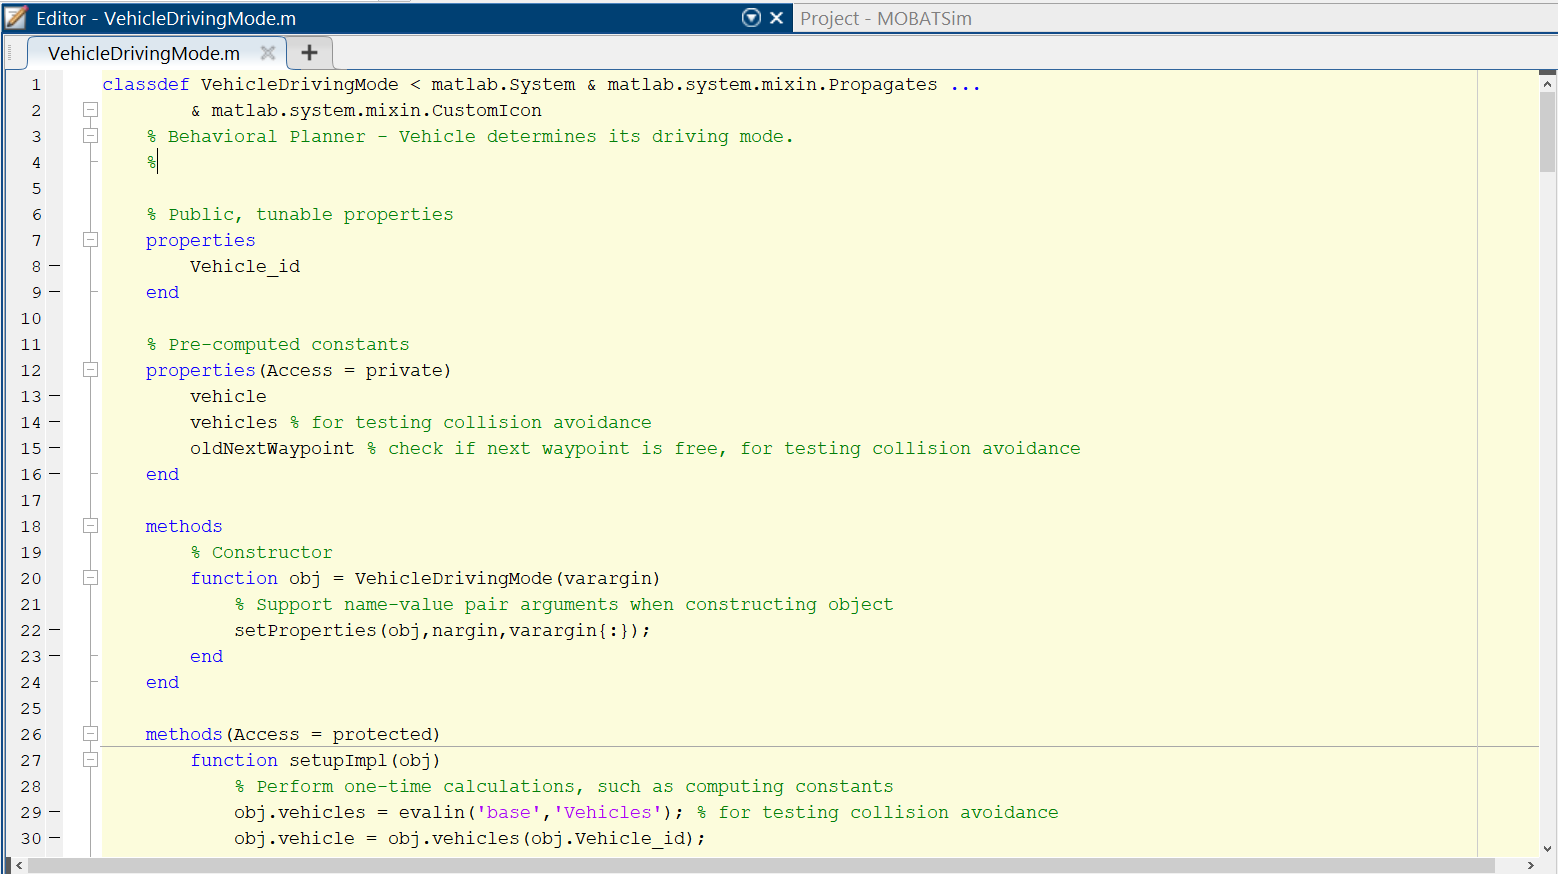

The `Vehicle_id` variable is the variable which keeps the IDs of different vehicles from getting confused by the program. The `MATLAB System Block` code seen in the editor acts as a `Class` in itself but with a different set of properties to support the Simulink block type of execution. In order to interrupt the block execution at a given time, we need to scrool down into the `stepImpl()` function which runs on the loop at every sample time.

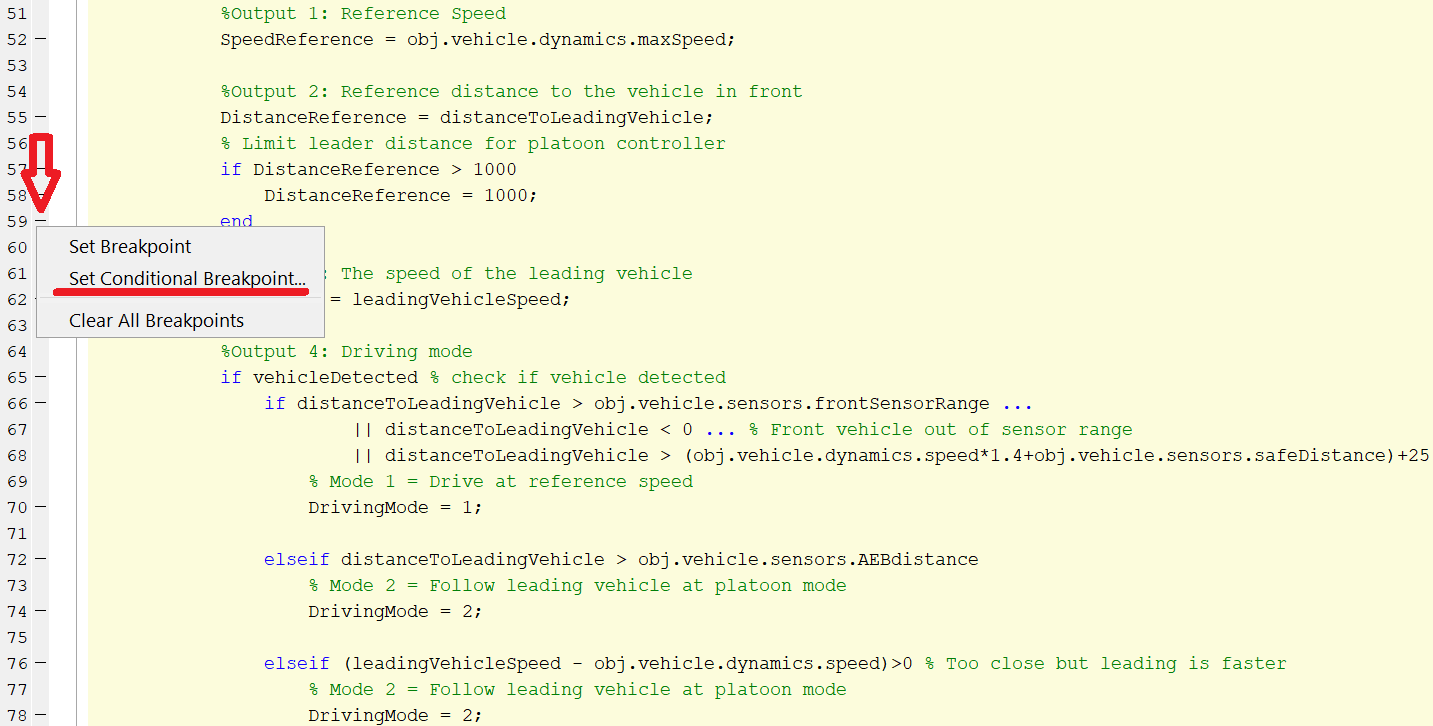

Let's put a conditional breakpoint on** line 65**. Right click on the dash next to number 65 on the left and then choose Set Conditional Breakpoint. A useful tip is to put conditional breakpoints to view the execution at a certain time.  For example, to see the states of **Vehicle 4** after time` t>6`, enter the following condition in the next window:

- `obj.vehicle.id == 4 && get_param('MOBATSim','SimulationTime')>6`

`Here obj.vehicle.id `refers to the ID of the vehicle that we want to get. The code `get_param('MOBATSim','SimulationTime')>6 `gets the simulation time of the Simulink model at every loop and checks if it is greater than 6. By putting an **and (**`&&`**) **between two conditions we are going to make sure that the simulation gets paused when **Vehicle 4** is executing the code after time `t>6`.

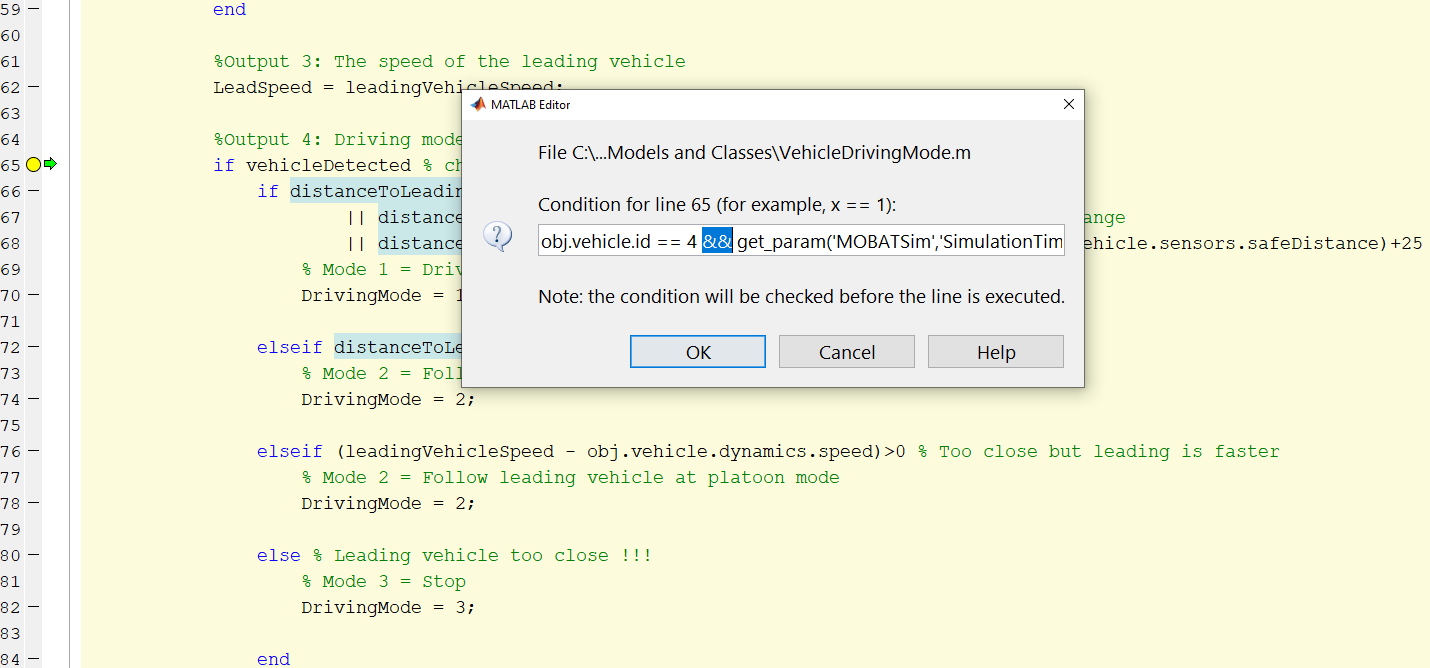

Now the yellow dot shows that the conditional breakpoint is set and all we have to do is to run the simulation. By executing the below code or just running the Simulink using the GUI, we will get to the Debugging mode.

Now you should see Debugging options marked with red below. The green arrow next to line number 65 indicates that we about to execute the code on line 65. At this moment, we can click on **Continue** or **Step** to continue executing the lines. However, in this task, we are going to check some states of **Vehicle 4** using the **Command Window** below.

## 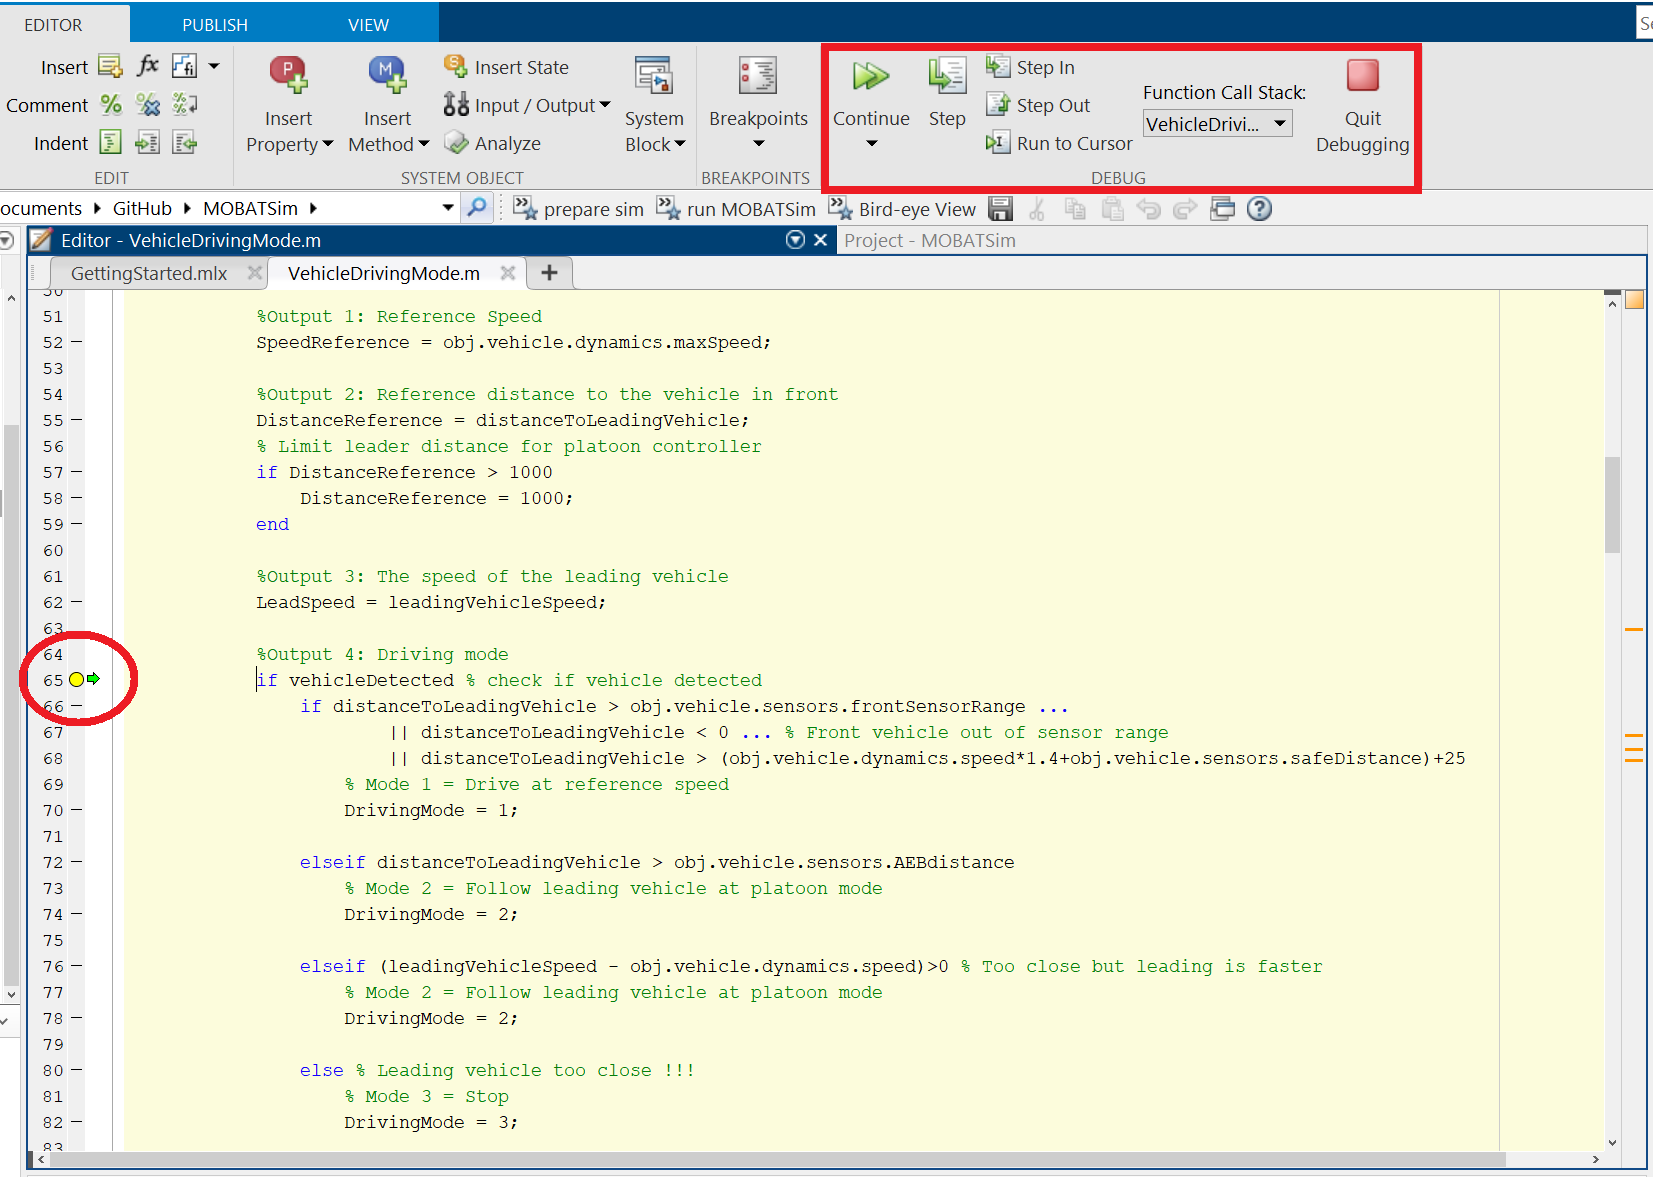

By typing `obj.vehicle.dynamics.speed `we check the current speed of **Vehicle 4** in m/s. To have a broader overlook to **Vehicle 4**, we can simply write `obj.vehicle` and we get the overlook of the structure of **Vehicle 4**. To learn more about the structure of a vehicle in MOBATSim, please refer to the class *src/Models and Classes/Vehicle.m*.

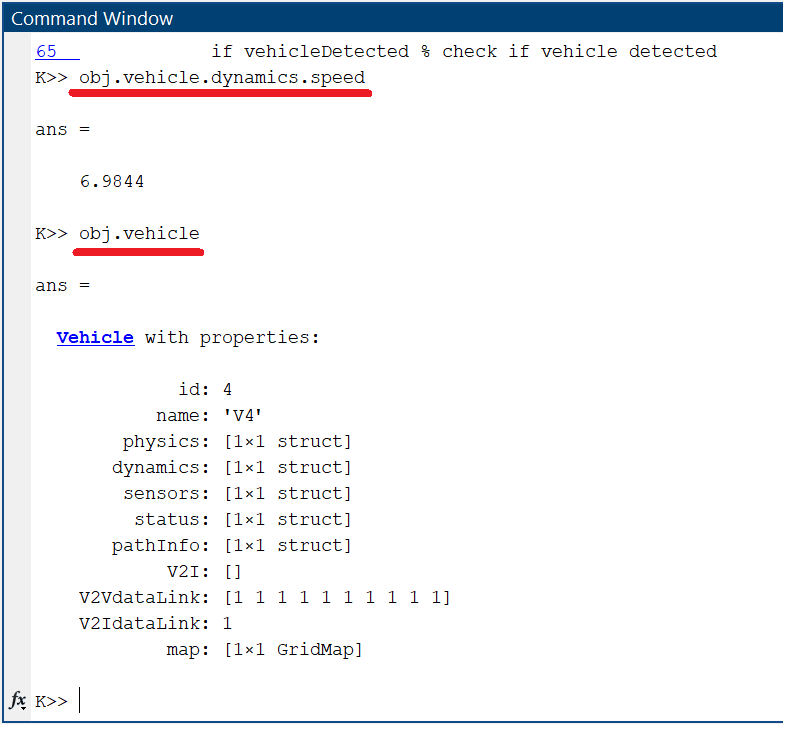

## 3- Change the Parameters of the Vehicle 2's Lateral Controller

In this Task, let's change **Vehicle 2**'s lateral controller parameters and see if there will be any change by the visualization. Firstly we need to navigate into the lateral controller subsystem.

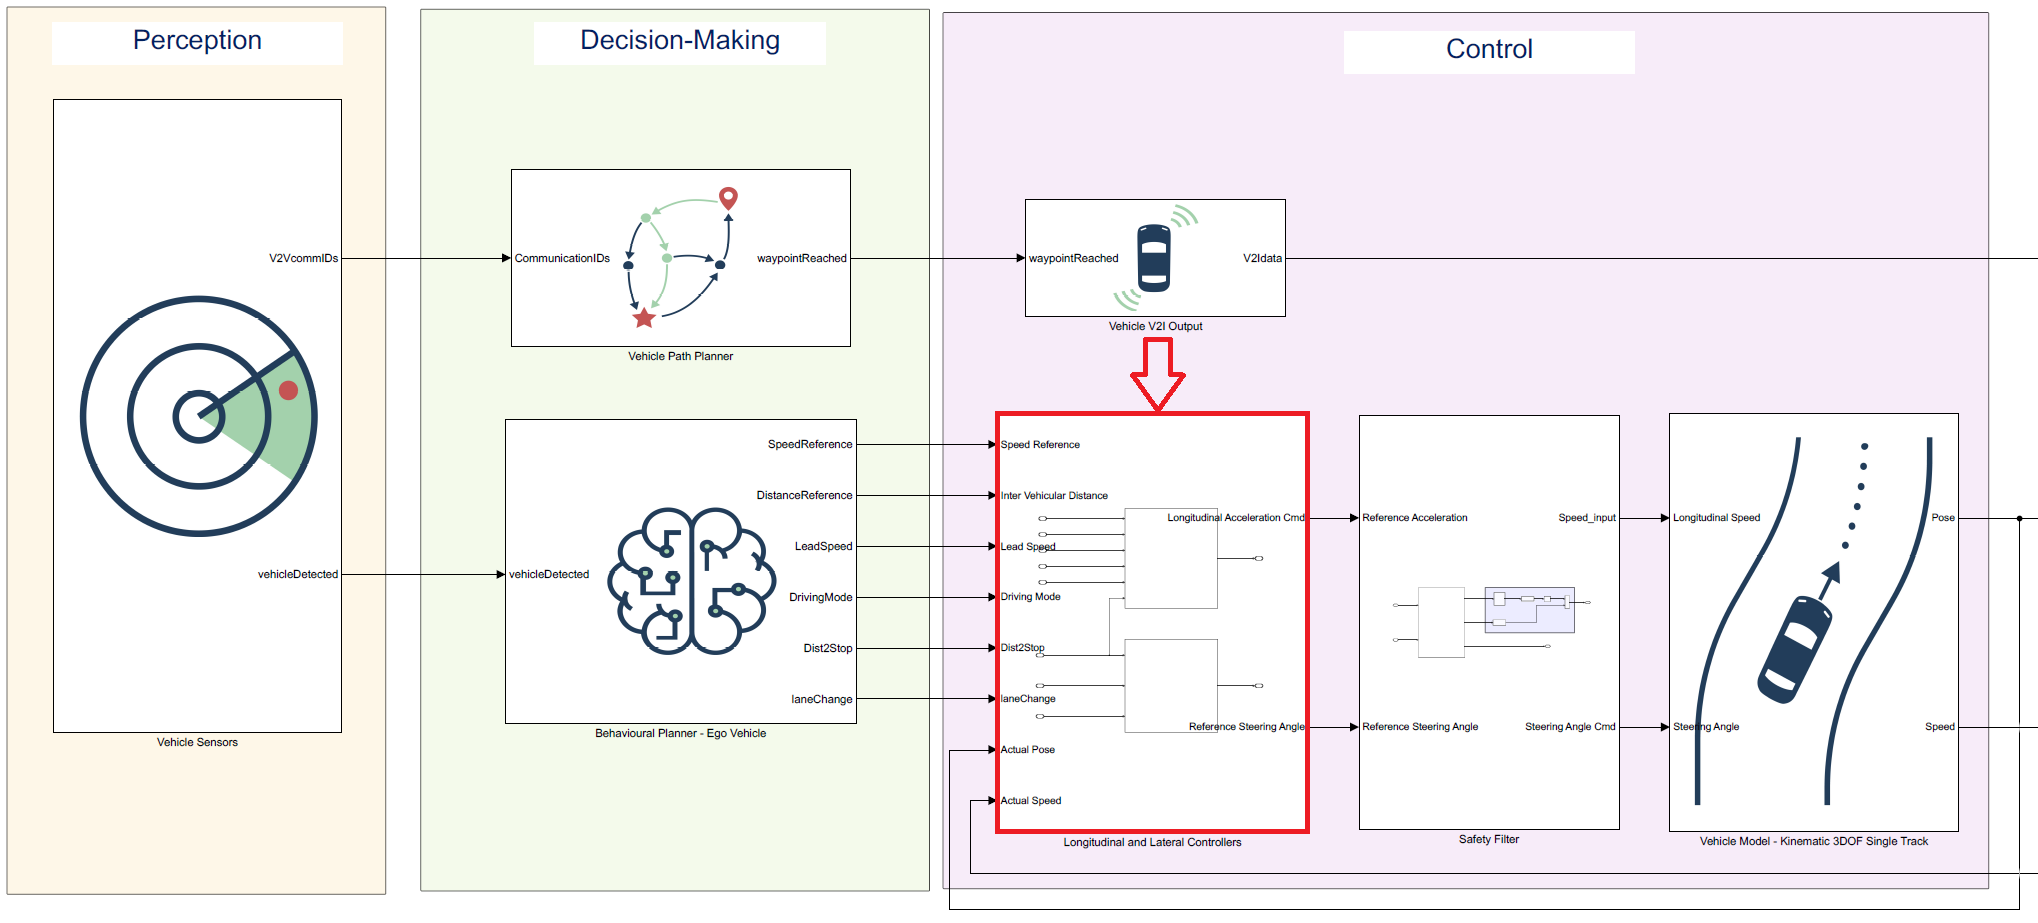

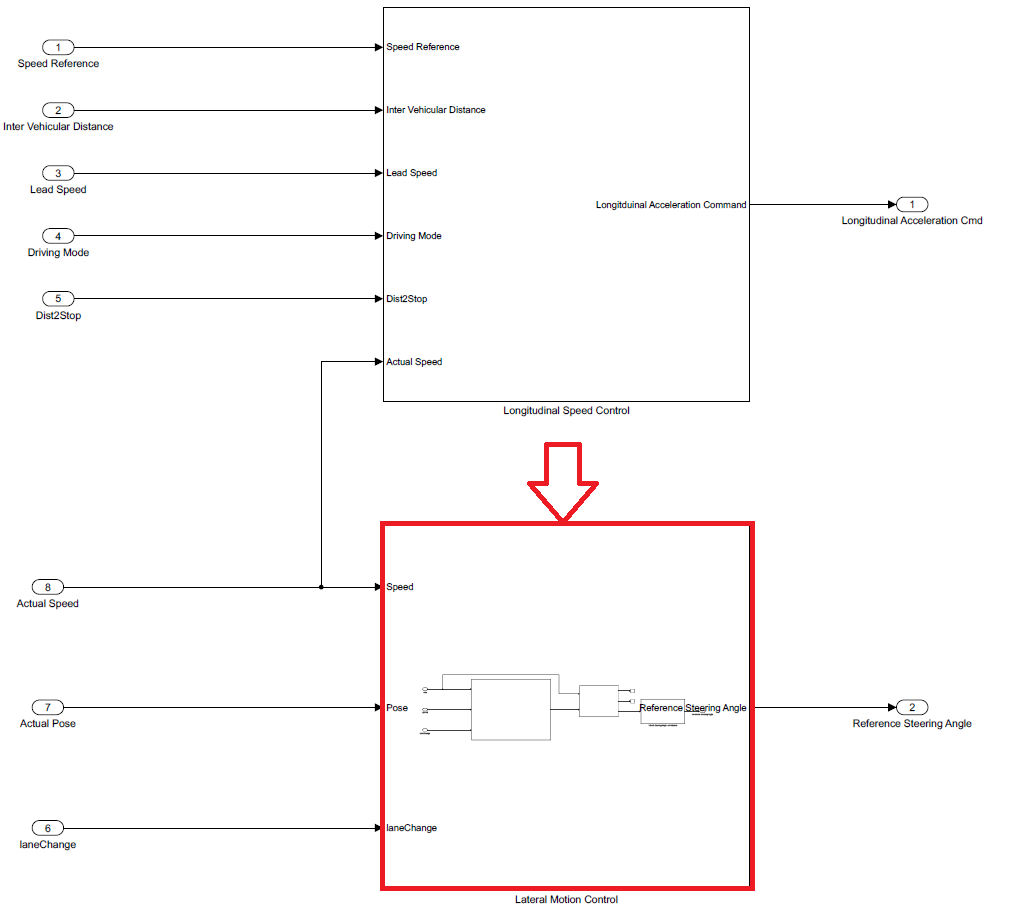

Here we have two blocks. First one is the **Pure Pursuit** **controller (1)** and the second one is a **subsystem (2)** which converts the reference direction into steering angle for the vehicle kinematic bicycle model.

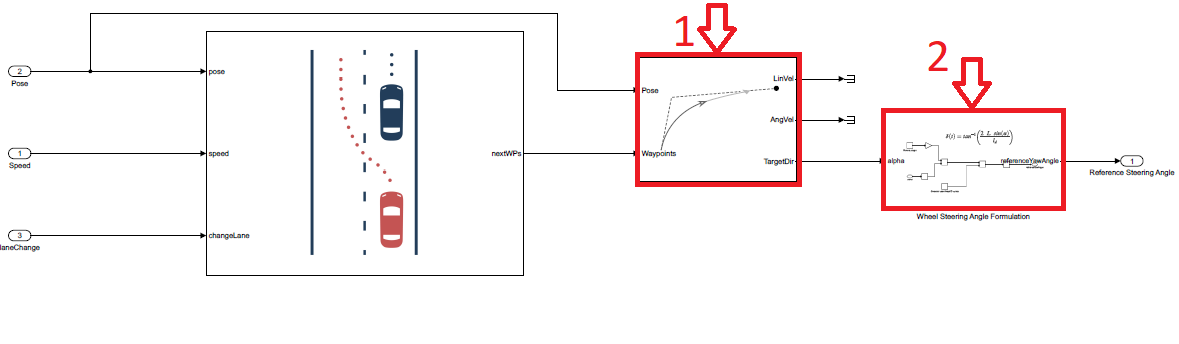

By clicking on the first block, we can directly set the parameters from the window. Here we can change the **maximum angular velocity** and make it smaller than **"1 rad/s"** to make the vehicle less capable of cornering. Normally this parameter depends on the vehicle size and other properties. However, the **lookahead distance** parameter for the **Pure Pursuit** controller is a design parameter that defines how sharply the vehicle turns. Making this value bigger makes the curves smoother but slower to turn; making it smaller makes the vehicle act quicker but do sharp movements, which may cause destabilization.

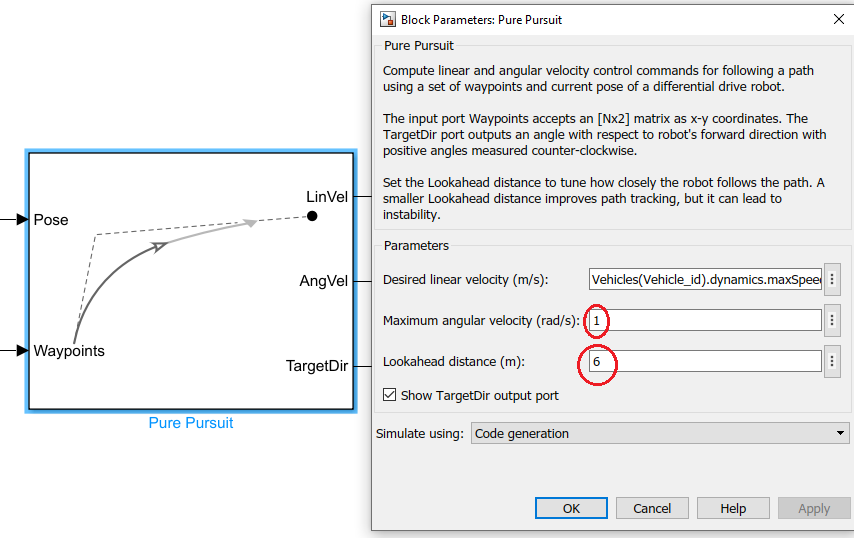

We enter another subsystem by clicking onto the second block where the conversion from direction angle alpha to steering angle happens. Here we can change the vehicle length according to the size of the vehicle, but more importantly, we should change the lookahead distance according to the formula as we changed in the previous section. In any case, you can test different values for the lookahead distance by changing the constant, running the simulation, visualizing how **Vehicle 2** turns, and then test other values.

## 4- Change the Path Planner Type of a Vehicle

Again from the Vehicle's Simulink Model, go to the Vehicle Path Planner block and right click on it. From the list choose the **Block Parameters (MATLABSystem) **option.

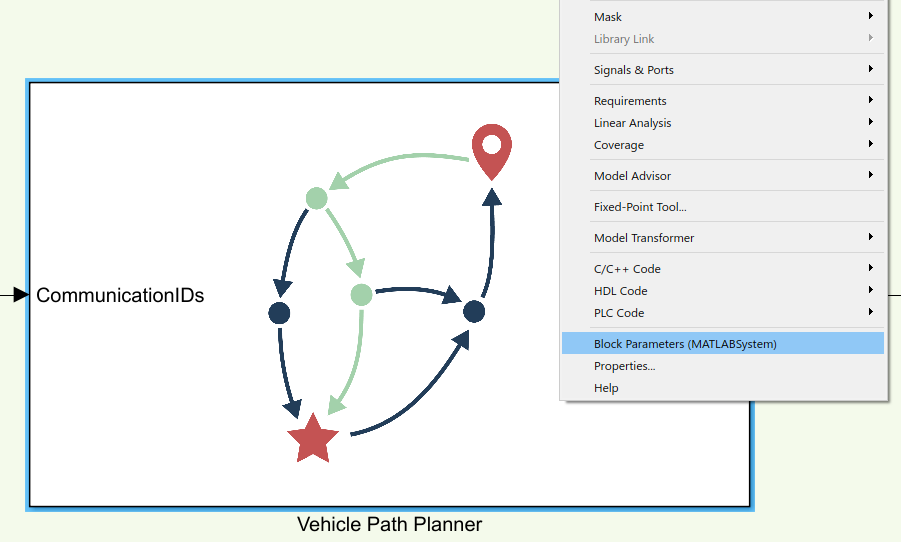

Inside, you can change the desired path planner class from **VehiclePathPlanner_Astar** to **VehiclePathPlanner_shortestPathFinder**.

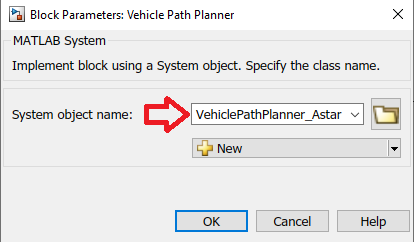

After you edited the class, you have to double click on the path planner block and change everything back to the version underneath.

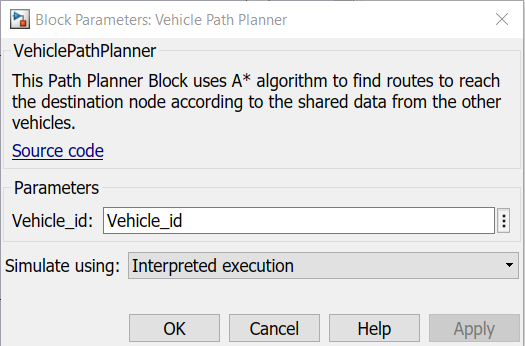

## 5- Inject Faults to Vehicle X during the Simulation

In this Task, we can simply edit the Simulink model of a vehicle that we would like to and add a white noise source to the reference speed signal. Fault injection can be used to alter any of the signals in Simulink; therefore, this is just a simple example of examining the effects of a white noise disturbance on the vehicle's speed.

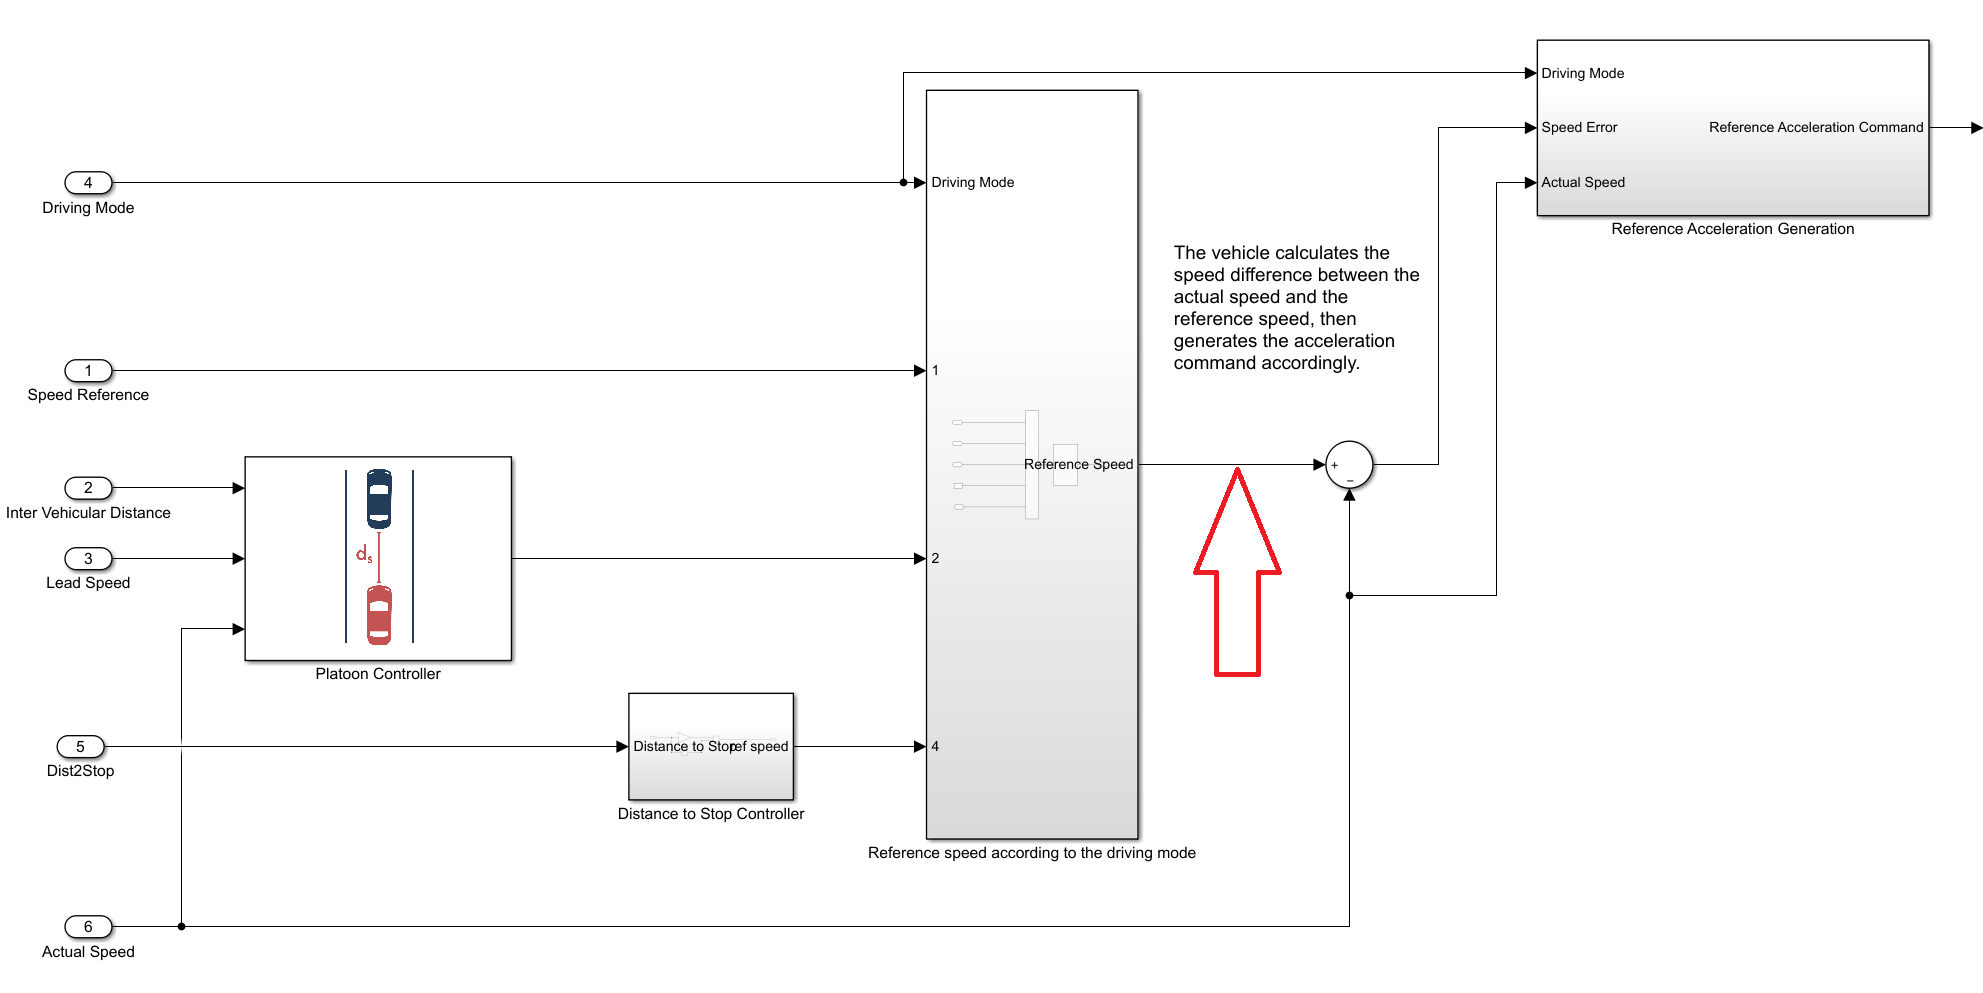

For the sake of simplicity, you can use a Band-Limited White Noise block and a sum block to inject faults. For more sophisticated fault injections, you can use a subsystem and/or a MATLAB function block.

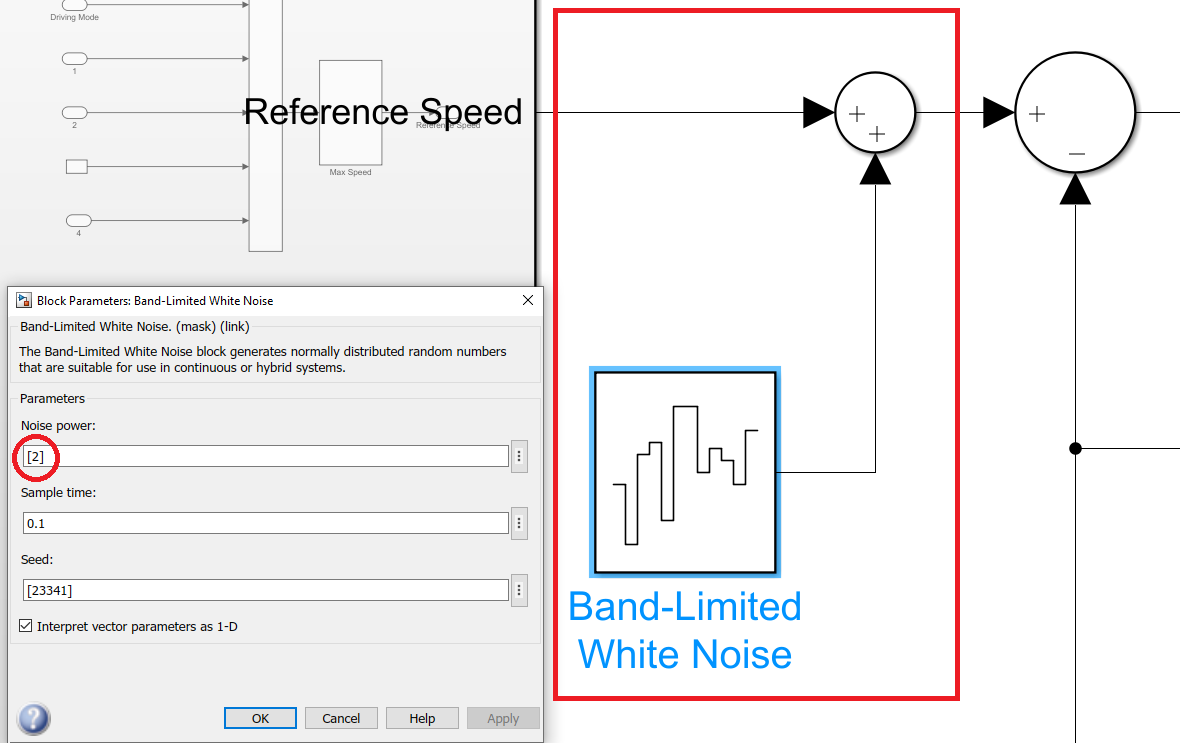

As we can see, even a noise with power **"2"** can cause higher deviations in the speed values.

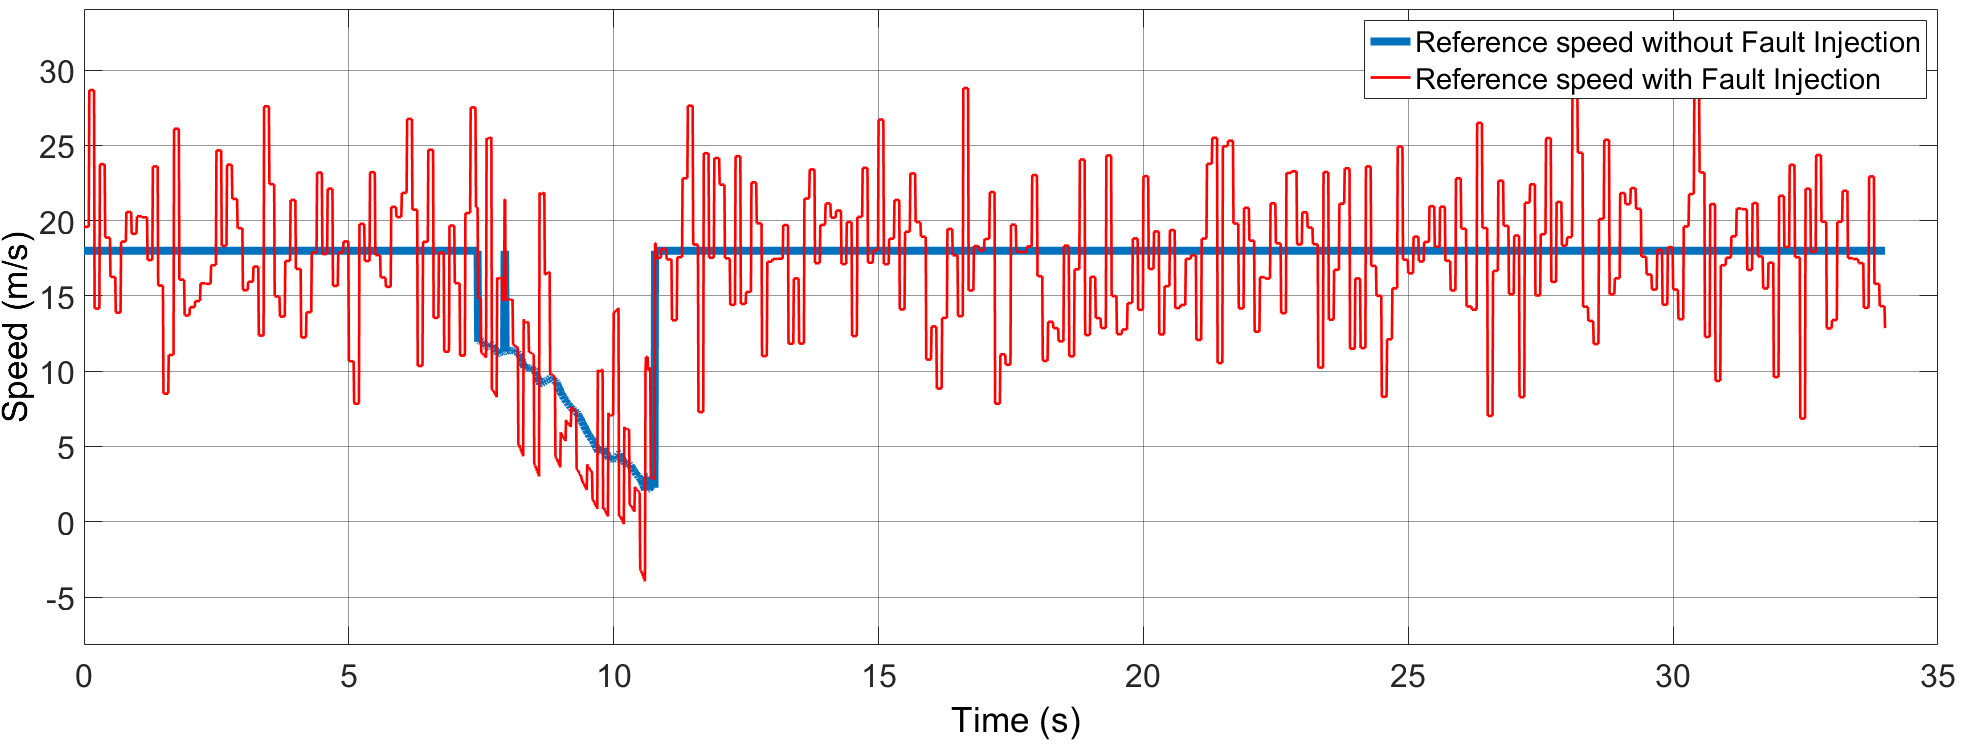

# -----------------------------------------------------------------------------

# Further Documentation

I hope you find **MOBATSim** useful for your purpose. If you discover bugs, you can let us know by raising issues on the **GitHub repository**, and we will try our best to address them! If you want to dive further into MOBATSim to see what you can change or develop, please continue with the live script [Documentation.mlx](matlab:open('./docs\Documentation.mlx')) in the **docs** folder.